# **STOKASTISK MODELLERING **

***MADS STEINER KRISTENSEN -  201405230***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

# **STOKASTISKE VARIABLE**

## **EFTERÅR 2015**

### MARGINALE TÆTHEDSFUNKTIONER

Vis at de marginale tæthedsfunktionerfor X og Y er givet som i tabellerne i opgavebeskrivelsen.


$$f_Y \left(y\right)=\sum_x f_{X,Y} \left(x,y\right),\;\;\;\;f_X \left(x\right)=\sum_y f_{X,Y} \left(x,y\right)$$


data = [
    [0,     1/12,   0   ];
    [2/12,  0,      2/12];
    [2/12,  1/12,   2/12];
    [0,     2/12,   0   ]
];

MarginalX = sum(data);
MarginalY = sum((data'));

TX = array2table(MarginalX, 'VariableNames',{'X1','X2','X3'}, 'RowNames',{'fX(x)'})

TX = 1×3 table
               X1         X2         X3   
             _______    _______    _______

    fX(x)    0.33333    0.33333    0.33333


x = sym(MarginalX)

$$x = \left(\begin{array}{ccc} \frac{1}{3} & \frac{1}{3} & \frac{1}{3} \end{array}\right)$$

TY = array2table(MarginalY, 'VariableNames',{'Y5','Y6','Y7', 'Y8'}, 'RowNames',{'fY(y)'})

TY = 1×4 table
                Y5         Y6         Y7         Y8   
             ________    _______    _______    _______

    fY(y)    0.083333    0.33333    0.41667    0.16667


y = sym(MarginalY)

$$y = \left(\begin{array}{cccc} \frac{1}{12} & \frac{1}{3} & \frac{5}{12} & \frac{1}{6} \end{array}\right)$$

### FORVENTNINGSVÆRDI

Vis at de i opgavebeskrivelsen givet udtryk er korrekt.


$$E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x=x_i \right)$$


estimationX = 0;

for n = 1:length(MarginalX)
    estimationX = estimationX + (n * MarginalX(n));
end

disp("E[X] = " + estimationX);

E[X] = 2


offset = 4;
estimationY = 0;

for n = 1:length(MarginalY)
    estimationY = estimationY + ((n + offset) * MarginalY(n));
end

disp("E[Y] = " + estimationY);

E[Y] = 6.6667


offset = 4;
estimationXY = 0;

for n = 1:length(MarginalX)
    for j = 1:length(MarginalY)
        estimationXY = estimationXY + ((n * (j + offset)) * data(j, n));
    end
end

disp("E[XY] = " + estimationXY);

E[XY] = 13.3333


estimationXSquared = 0;

for n = 1:length(MarginalX)
    estimationXSquared = estimationXSquared + ((n^2) * MarginalX(n));
end

disp("E[X^2] = " + estimationXSquared);

E[X^2] = 4.6667


offset = 4;
estimationYSquared = 0;

for n = 1:length(MarginalY)
    estimationYSquared = estimationYSquared + ((n + offset)^2 * MarginalY(n));
end

disp("E[Y^2] = " + estimationYSquared);

E[Y^2] = 45.1667


### KORRELATIONS KOEFFICIENT

Hvad er korrelationskoefficienten for X og Y?


$$\rho =\frac{E\left\lbrack \mathrm{XY}\right\rbrack -E\left\lbrack X\right\rbrack \cdot E\left\lbrack Y\right\rbrack }{\sigma_X \cdot \sigma_Y }$$



$$\sigma {\;}_X^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 ,\;\;\;\;\;\sigma {\;}_Y^2 =E\left\lbrack Y^2 \right\rbrack -E{\left\lbrack Y\right\rbrack }^2$$



$$\rho =\frac{E\left\lbrack \mathrm{XY}\right\rbrack -E\left\lbrack X\right\rbrack \cdot E\left\lbrack Y\right\rbrack }{\sqrt{E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 }\cdot \sqrt{E\left\lbrack Y^2 \right\rbrack -E{\left\lbrack Y\right\rbrack }^2 }}$$


upper = estimationXY - (estimationX * estimationY);

sigmaX = sqrt(estimationXSquared - estimationX^2);

sigmaY = sqrt(estimationYSquared - estimationY^2);

correlation = upper / (sigmaX * sigmaY);

disp("p = " + correlation);

p = 0


### KORRELEREDE VARIABLE

Er de stokastiske variable X og Y korrelerede?

Da korrelationskoefficienten er lig med 0, er X og Y ukorrelerede.

### UAFHÆNGIGHED

Er de stokastiske variable X og Y uafhængige?

if MarginalX(1) * MarginalY(1) == data(1, 1)
    disp("X og Y er uafhængige, da fx(x) * fy(y) er identisk med fxy(x, y)");
else
    disp("X og Y er ikke uafhængige, da fx(x) * fy(y) ikke er identisk med fxy(x, y)");
end

X og Y er ikke uafhængige, da fx(x) * fy(y) ikke er identisk med fxy(x, y)


### BETINGET SANDSYNLIGHED

Opskriv den betinget sandsynlighed for 

   
$$f_{X|Y} \left(x|y=6\right)$$


Den betinget sandsynlighed kan opskrives som


$$f_{X|Y} \left(x|y\right)=\frac{f_{X,Y} \left(x,y\right)}{f_X \left(x\right)}$$


for n = 1:3
    probabilityX(n) = data(6 - offset, n) / MarginalY(6 - offset);
    names(n) = cellstr(("X" + num2str(n)));
end

TP = array2table(probabilityX, 'VariableNames', names, 'RowNames',{'fX|Y(x|y)'})

TP = 1×3 table
                 X1     X2    X3 
                 ___    __    ___

    fX|Y(x|y)    0.5    0     0.5


prob = sym(probabilityX)

$$prob = \left(\begin{array}{ccc} \frac{1}{2} & 0 & \frac{1}{2} \end{array}\right)$$

## **EFTERÅR 2015 REEKSAMEN**

En kontinuært stokastisk variabel har følgende fordelingsfunktion (cdf): 


$$\left.F_X \left(x\right)=\left\lbrace \begin{array}{cc}
k\cdot e^x  & -\infty <x\le 1\\
1 & 1<x
\end{array}\right.\right\rbrace$$


### TÆTHEDSFUNKTION

Vis at tæthedsfunktionen (pdf) er givet ved


$$\left.f_X \left(x\right)=\left\lbrace \begin{array}{cc}
k\cdot e^x  & -\infty <x\le 1\\
0 & 1<x
\end{array}\right.\right\rbrace$$


Tæthedsfunktionen findes som $f_x \left(x\right)=\frac{{\mathrm{dF}}_X \left(x\right)}{\mathrm{dx}}$, hvorved

syms x k
f = k * exp(x);
diff(f, x)

$$ans = k\,{\mathrm{e}}^{x}$$

f = sym('1');
diff(f)

$$ans = 0$$

Hvilket dermed givet, at 


$$\left.f_X \left(x\right)=\left\lbrace \begin{array}{cc}
k\cdot e^x  & -\infty <x\le 1\\
0 & 1<x
\end{array}\right.\right\rbrace$$


### GYLDIG TÆTHEDSFUNKTION

For hvilken værdi af k er $f_x \left(x\right)$en gyldig tæthedsfunktion?

En PDF er gyldig når 


$$\;\int_{-\infty }^{\infty } f_x \left(x\right)\mathrm{dx}=1$$


og alle værdier af PDF'en er større eller lig med 0. Det vil sige, at 


$$\int_{-\infty }^1 k\cdot e^x \mathrm{dx}+\int_1^{\infty } 0\;\mathrm{dx}=1$$



$$k{\left\lbrack e^x \right\rbrack }_{-\infty }^1 =1$$



$$\underset{t\to \infty }{\mathrm{lim}} k\left(e^1 -e^{-t} \right)=1$$



$$k\cdot e=1\Rightarrow k=\frac{1}{e}$$


### SANDSYNLIGHEDER

k = 1 / exp(1);

probability = k * exp(0.4); 

disp("Pr(x < 0.4) = " + probability);

Pr(x < 0.4) = 0.54881


probability = probability - (k * exp(0.1));

disp("Pr(0.1 <= x < 0.4) = " + probability);

Pr(0.1 <= x < 0.4) = 0.14224


### FORVENTNINGSVÆRDI

Middelværdien / Forventningsværdien bestemmes som følgende,


$$E\left\lbrack X\right\rbrack =\overline{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}$$



$$E\left\lbrack X\right\rbrack =\int_{-\infty }^1 x\cdot f_x \left(x\right)\mathrm{dx}=\int_{-\infty }^1 x\cdot \frac{1}{e}\cdot e^x \mathrm{dx}$$


f = @(a) a.*1/exp(1).*exp(a);

value.expectation = round(integral(f, -inf, 1), 10);

disp("Forventningsværdien er bestemt til at være: " + value.expectation);

Forventningsværdien er bestemt til at være: 0



$$\mathrm{Var}\left(x\right)=\int_{-\infty }^{\infty } \left(x-\overline{x} \right)\cdot f_X \left(x\right)\mathrm{dx}=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


f = @(a) (a.^2).*1/exp(1).*exp(a);

value.expectationsquared = round(integral(f, -inf, 1), 10);

disp("Variansen er bestemt til at være: " + (value.expectationsquared - value.expectation^2));

Variansen er bestemt til at være: 1


## **EFTERÅR 2016**

En diskret stokastisk variabel har følgende tæthedsfunktion (pmf): 


$$\left.\left\lbrace \begin{array}{cccc}
x & -1 & 1 & 7\\
f_X \left(x\right) & k & \frac{3}{4} & \frac{1}{8}
\end{array}\right.\right\rbrace$$


### GYLDIG TÆTHEDSFUNKTION

For hvilken værdi af $k$ er $f_X \left(x\right)$en gyldig tæthedsfunktion? 

For en tæthedsfunktion gælder at summen af alle værdier tilsammen er lig 1, derved opnås at


$$\sum_x f_X \left(x\right)=1$$


Hvormed 

  
$$k=\sum_x f_X \left(x\right)-\frac{3}{4}-\frac{1}{8}$$


k = 1 - (3/4) - (1/8);

disp("For værdien af k = " + k + " er fx(x) en gyldig tæthedsfunktion");

For værdien af k = 0.125 er fx(x) en gyldig tæthedsfunktion


### FORDELINGSFUNKTION

For fordelingsfunktionen gælder der, at 


$$F_X \left(x\right)=\mathrm{Pr}\left(X\le x\right)=\sum_{i=x}^{n_x } f_X \left(x_i \right)$$


CumDist(1) = 0; 
CumDist(2) = k;
CumDist(3) = k + (3/4);
CumDist(4) = k + (3/4) + (1/8);
CumDist(5) = 1;


X = [-2, -1, 1, 7, 10];


$$F_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & x<\left(-1\right)\\
\frac{1}{8} & -1\le x<1\\
\frac{7}{8} & 1\le x<7\\
1 & 7\le x
\end{array}\right\rbrack \right\rbrace$$


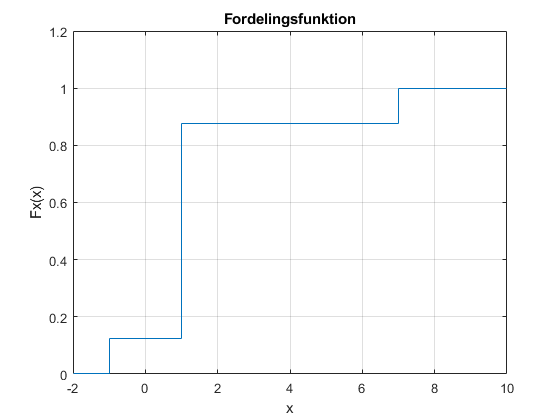

figure(1)
stairs(X, CumDist);
grid on
title('Fordelingsfunktion')
ylabel('Fx(x)')
xlabel('x')
xlim([-2.00 10.00])
ylim([0.000 1.200])

### FORVENTNINGSVÆRDI OG STANDARD AFVIGELSE

For forvetningsværdien gælder der, at


$$\overline{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$


k = 1/8;
X = [-1, 1, 7]; 
Pr = [k, 3/4, 1/8];
ExpectationValue = 0;

for n = 1:length(X)
    ExpectationValue = ExpectationValue + (X(n) * Pr(n));     
end

disp("Forventningsværdien er bestemt til at være " + ExpectationValue);

Forventningsværdien er bestemt til at være 1.5


For variansen gælder, at 


$$\mathrm{Var}\left(X\right)=\sigma_x^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


Hvormed standard afvigelsen kan findes som 

 
$$\sigma_x =\sqrt{E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 }$$


ExpectationValueSquared = 0;

for n = 1:length(X)
    ExpectationValueSquared = ExpectationValueSquared + ((X(n)^2) * Pr(n));     
end

Deviation = sqrt(ExpectationValueSquared - ExpectationValue^2);

disp("Standard afvigelsen er bestemt til at være " + Deviation);

Standard afvigelsen er bestemt til at være 2.1794


### TRANSFORMATION FORVENTNINGSVÆRDI

Da der gælder, at 


$$g\left(X=x\right)=3\cdot x^2$$


Forventningsværdier kan da bestemmes som


$$E\left\lbrack g\left(x\right)\right\rbrack =E\left\lbrack 3\cdot x^2 \right\rbrack$$


Da 3 er konstant kan følgende udtryk opnåes


$$E\left\lbrack g\left(x\right)\right\rbrack =3\cdot E\left\lbrack x^2 \right\rbrack$$


GExpectedValue = 3 * ExpectationValueSquared;

disp("Forventningsværdien for x = g(x) er bestemt til at være " + GExpectedValue);

Forventningsværdien for x = g(x) er bestemt til at være 21


### VÆRDIER X KAN ANTAGE

X kan antage følgende værdier


$$-1,1,7$$


## **EFTERÅR 2016 REEKSAMEN**

En kontinuært stokastisk variabel har følgende tæthedsfunktion (pmf): 


$$f_X \left(x\right)=\left\lbrace \begin{array}{cc}
A\cdot x+B & -2<x\le 3\\
0 & \mathrm{ellers}
\end{array}\right\rbrace$$


### GYLDIG TÆTHEDSFUNKTION

For en gyldig tæthedsfunktion gælder, at


$$\int_{-\infty }^{\infty } f_x \left(x\right)\mathrm{dx}=1$$


Hvor der i denne situation derfor gælder, at


$$\int_{-2}^3 f_x \left(x\right)\mathrm{dx}=1=A$$


Det ses på figur 1, at fordelingsfukntionen er en trekant med en ukendt side og arealet af en retvinklet trekant bestemmes som,


$$A=\frac{1}{2}\cdot b\cdot h$$


Hvor b er bredden (5) [-2;3] og h er højden. I dette tilfælde er h den ukendte og løses ved følgende.


$$h=\frac{2\cdot A}{5}$$


A = 1;
b = 5;

h = (2 * A) / b;

disp("For værdien k = " + h + " til fx(-2) er det en gyldighed tæthedsfunktion");

For værdien k = 0.4 til fx(-2) er det en gyldighed tæthedsfunktion


### FORDELINGSFUNKTION

 For fordelingsfunktionen gælder, at


$$F_X \left(x\right)=\int_{-\infty }^x f_x \left(x\right)\mathrm{dx}$$


syms A B C x

f = A * x + B;

int(f, x) + C

$$ans = \frac{A\,x^{2}}{2}+B\,x+C$$

Hvilket dermed giver, at 


$$F_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & x<\left(-2\right)\\
\frac{1}{2}A\cdot x^2 +B\cdot x+C & -2\le x\le 3\\
1 & 3<x
\end{array}\right\rbrack \right\rbrace$$


### FORVENTNINGSVÆRDI OG VARIANS

For forvetningsværdien gælder, at


$$E\left\lbrack X\right\rbrack =\bar{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}$$


clear x A B

A = (-2/25);
B = 6/25;

f = @(x)  x.* (A .* x + B);

value.expectation = round(integral(f, -2, 3), 10);

disp("Forventningsværdien er bestemt til at være: " + value.expectation);

Forventningsværdien er bestemt til at være: -0.33333


For variansen gælder, at


$$\mathrm{Var}\left(x\right)=\int_{-\infty }^{\infty } \left(x-\bar{x} \right)\cdot f_X \left(x\right)\mathrm{dx}=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


f = @(x)  (x.^2) .* (A .* x + B);

value.expectationsquared = round(integral(f, -2, 3), 10);

disp("Variansen er bestemt til at være: " + (value.expectationsquared - value.expectation^2));

Variansen er bestemt til at være: 1.3889


### SANDSYNLIGHED

For sandsynligheden gælder, at 


$$F_X \left(x\right)=\int_{-\infty }^x f_x \left(x\right)\mathrm{dx}=P\left(X\le x\right)$$


Hvormed der i dette tilfælde anvendes, at 


$$F_X \left(0\right)=\int_{-\infty }^0 f_x \left(0\right)\mathrm{dx}=P\left(X<0\right)$$


Hvortil det er kendt, at


$$F_X \left(0\right)=\frac{1}{2}A\cdot 0^2 +B\cdot 0+C=C$$


A = (-2/25);
B = 6/25;
C = 16/25;

FZero = 1/2 * A * 0^2 + B * 0 + C;

disp("Sandsynligheden er dermed bestemt til at være " + FZero);

Sandsynligheden er dermed bestemt til at være 0.64


## **EFTERÅR 2017**

En diskret stokastisk variabel X kan antage værdierne


$$\left\lbrace 0,\;1,\;2,\;3,\;4,\;5\right\rbrace$$


med følgende sandsynligheder


$$\begin{array}{l}
P\left(X=1\right)=P\left(X=2\right)=P\left(X=3\right)=0\ldotp 15,\\
P\left(X=4\right)=0\ldotp 25,\\
P\left(X=5\right)=0\ldotp 10
\end{array}$$


### SANDSYNLIGHED

Bestemt sandsynligheden for at X har værdien 0 $P\left(X=0\right)$. 

Der anvendes, at arealet for en tæthedsfunktion er lig med 1, hvormed


$$\sum_{i=1}^n f_X \left(x_i \right)=\sum_{i=1}^n P\left(X=x_i \right)=1$$


Da sandsynligheden for at X har værdien 0 er det sidste udfald, 

kan den findes ved at trække alle andre sandsynligheder fra summen som skal give 1.

PZero = 1 - (3*0.15 + 0.25 + 0.10);

disp("Sandsynligheden for at X har værdien 0 er lig med " + PZero);

Sandsynligheden for at X har værdien 0 er lig med 0.2


### TÆTHEDS- OG FORDELINGSFUNKTION

Tæthedsfunktionen er bestemt ved


$$\sum_{i=1}^n f_X \left(x_i \right)=\sum_{i=1}^n P\left(X=x_i \right)=1$$


Fordelingsfunktionen er bestemt ved


$$F_X \left(x\right)=P\left(X\le x\right)$$


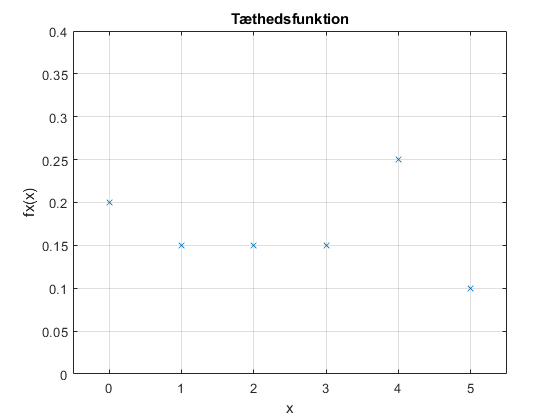

X = [0, 1, 2, 3, 4, 5];
P = [0.20, 0.15, 0.15, 0.15, 0.25, 0.10];
Pcdf = [0, 0, 0, 0, 0, 0];

figure(1)
stairs(X, P, 'x');
grid on
title('Tæthedsfunktion')
ylabel('fx(x)')
xlabel('x')
xlim([-0.50 5.50])
ylim([0.000 0.400])

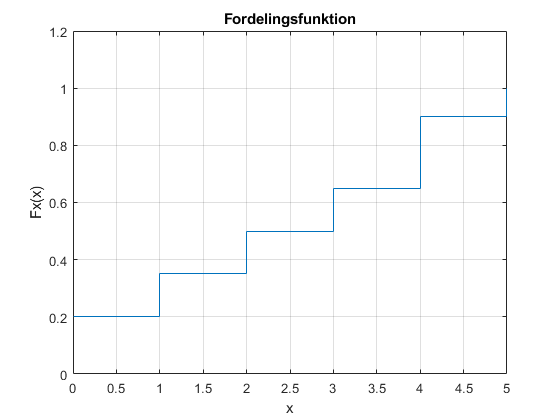


for n = 1:length(P)
    Pcdf(n) = sum(P(1:n));
end

figure(2)
stairs(X, Pcdf);
grid on
title('Fordelingsfunktion')
ylabel('Fx(x)')
xlabel('x')
xlim([-0.00 5.00])
ylim([0.000 1.200])

### MIDDELVÆRDI

Bestem middelværdien $E\left\lbrack X\right\rbrack$ af den stokastiske variabel X.

Dertil anvendes formlen for middelværdien af en stokastisk variabel som er givet ved


$$\bar{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$


EstimationX = 0;

for n = 1:length(P)
    EstimationX = EstimationX + (X(n) * P(n));
end

disp("Middelærdien er bestemt til at være " + EstimationX);

Middelærdien er bestemt til at være 2.4


### VARIANS

Bestem variansen af den stokastiske variabel X.

Variansen er givet ved følgende udtryk.


$$\mathrm{Var}\left(X\right)=\sigma_x^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


EstimationXSquared = 0;

for n = 1:length(P)
    EstimationXSquared = EstimationXSquared + (X(n)^2 * P(n));
end

VarianceX = EstimationXSquared - EstimationX^2;

disp("Variansen er bestemt til at være " + VarianceX);

Variansen er bestemt til at være 2.84


## **EFTERÅR 2018**

En diskret stokastisk variabel X har en tæthedsfunktion som vist på nedenstående figur.

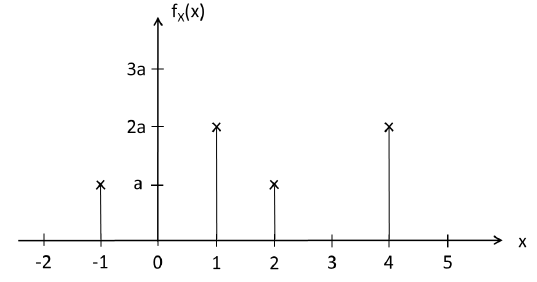

### GYLDIG TÆTHEDSFUNKTION

For at bestemme $a$ så $f_x \left(x\right)$er en gyldig tæthedsfunktionen anvendes, at


$$\sum_{i=1}^n f_x \left(x_i \right)=\sum_{i=1}^n P\left(X=x_i \right)=1$$


syms a
fx = a+2*a+a+2*a == 1;

solve(fx, a)

$$ans = \frac{1}{6}$$

Dette betyder, at $f_x \left(x\right)$er en gyldig tæthedsfunktion for $a=\frac{1}{6}$.

### FORDELINGSFUNKTION

For at bestemme fordelingsfunktionen anvendes, at


$$F_x \left(x\right)=\sum_{x_i \le x}^n f_x \left(x_i \right)$$


Hvilket dermed giver, at 


$$F_x \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & x<-1\\
a & -1\le x<1\\
3a & 1\le x<2\\
4a & 2\le x<4\\
6a & x\ge 4
\end{array}\right\rbrack \right\rbrace$$


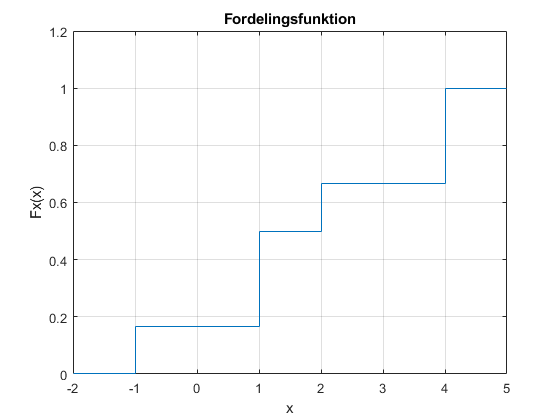

a = 1/6;

X = [-2, -1, 0, 1, 2, 3, 4, 5];
P = [0, a, 0, 2*a, a, 0, 2*a, 0];
Pcdf = [0, 0, 0, 0, 0, 0, 0, 0];

for n = 1:length(P)
    Pcdf(n) = sum(P(1:n));
end

figure(1)
stairs(X, Pcdf);
grid on
title('Fordelingsfunktion')
ylabel('Fx(x)')
xlabel('x')
xlim([-2.00 5.00])
ylim([0.000 1.2])

### MIDDELVÆRDI

For at finde middelværdien anvendes, at


$$\bar{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$


ExpectationValue = 0;

for n = 1:length(P)
    ExpectationValue = ExpectationValue + (X(n)*P(n));
end

ExpectationValue

ExpectationValue = 1.8333

Middelværdien er dermed bestemt til at være 1.8333.

### VARIANS

For at finde variansen anvendes, at


$$\mathrm{Var}\left(X\right)=\sigma_x^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


ExpectationValueSquare = 0;

for n = 1:length(P)
    ExpectationValueSquare = ExpectationValueSquare + (X(n)^2 * P(n));
end

Variance = ExpectationValueSquare - ExpectationValue^2

Variance = 3.1389

Variansen er dermed bestemt til at være 3.1389.

## **FORÅR 2016**

En kontinuert stokastisk variabel $X$har følgende fordelingsfunktion


$$F_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & 2\ge x\\
k\cdot x-\frac{2}{3} & 2<x\le 5\\
1 & 5<x
\end{array}\right\rbrack \right\rbrace$$


### TÆTHEDSFUNKTION

For at vise at tæthedsfunktionen er givet ved


$$f_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & 2\ge x\\
k & 2<x\le 5\\
0 & 5<x
\end{array}\right\rbrack \right\rbrace$$


Anvendes, at


$$f_X \left(x\right)=\frac{\textrm{d}}{\textrm{d}x}F_X \left(x\right)$$


syms x k

a = 0;
b = k * x - (2/3);
c = 1;

diff(a), diff(b), diff(c)


ans =

     []



$$ans = k$$


ans =

     []



Da $\lbrack \rbrack$ betyder at værdien er 0 er tæthedsfunktionen $f_X \left(x\right)$hermed eftervist at være korrekt.

### **GYLDIG TÆTHEDSFUNKTION**

For at bestemme for hvilken værdi af $k$ hvor $f_X \left(x\right)$ er en gyldig tæthedsfunktionen anvendes, at 


$$\int_{-\infty }^{\infty } f_X \left(x\right)\mathrm{dx}=1$$


Da gælder i dette tilfælde, at


$$\int_a^b f_X \left(x\right)=1$$


hvor $a=2$ og $b=5$.


$$\int_2^5 f_X \left(x\right)=1\Rightarrow \int_2^5 k=1$$


Hvilket giver at for værdien af k lig med


$$k=\frac{1}{3}$$


Opnåes en gyldig tæthedsfunktion.

### SKITSE AF TÆTHEDSFUNKTION

En skitse af tæthedsfunktionen vises i matlab.

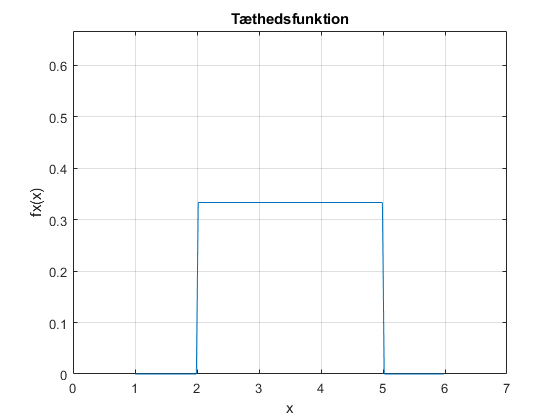

a = 2;
b = 5;
x = a-1:(b-a)/100:b+1;
fx = unifpdf(x, a, b);

figure(1)
plot(x, fx);
axis([a-2, b+2, 0, 2/(b-a)]);
grid on
title('Tæthedsfunktion')
ylabel('fx(x)')
xlabel('x')

### SANDSYNLIGHED

For at bestemme sandsynligheden $P\left(x\ge 3\right)$antages, at $k=3$ og der anvendes følgende


$$P\left(x\ge 3\right)=1-P\left(x<3\right)$$



$$P\left(x\ge 3\right)=1-F_X \left(3\right)$$


k = 1/3;
Fx = @(x) k*x-(2/3);

Probability = 1 - Fx(3)

Probability = 0.6667

Dermed er sandsynligheden $P\left(x\ge 3\right)$bestemt til at være $\frac{2}{3}$.

### FORVENTNINGSVÆRDI & VARIANS

For at bestemme forvetningsværdien anvendes, at 


$$E\left\lbrack X\right\rbrack =\bar{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}\Rightarrow E\left\lbrack X\right\rbrack =\int_2^5 x\cdot k$$


hvor værdien for $k$ antages, at være $\frac{1}{3}$.

k = 1/3;
fx = @(x) x * k;
EstimationValue = sym(integral(fx, 2, 5))

$$EstimationValue = \frac{7}{2}$$

Forventningsværdien er dermed bestemt til, at være $\frac{7}{2}$. Variansen bestemmes dernæst ved følgende,


$$\mathrm{Var}\left(x\right)=\int_{-\infty }^{\infty } \left(x-\bar{x} \right)\cdot f_X \left(x\right)\mathrm{dx}=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


fx = @(x) x.^2 * k;
Variance = sym(integral(fx, 2, 5)) - EstimationValue^2

$$Variance = \frac{3}{4}$$

Variansen er dermed bestemt til, at være $\frac{3}{4}$.

## **FORÅR 2016 REEKSAMEN**

En diskret stokastisk variabel $X$har følgende tæhedsfunktion.

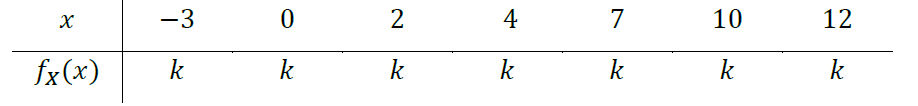

### GYLDIG TÆTHEDSFUNKTION

For at bestemme for hvilken værdi af $k$, hvor $f_X \left(x\right)$er en gyldig tæthedsfunktione anvend, at


$$\sum_{i=1}^n f_x \left(x_i \right)=\sum_{i=1}^n P\left(X=x_i \right)=1$$


syms k

fx = k + k + k + k + k + k + k == 1;

solve(fx, k)

$$ans = \frac{1}{7}$$

For værdien af $k$ lig med $\frac{1}{7}$ er $f_X \left(x\right)$en gyldig tæthedsfunktion.

### SKITSERING AF TÆTHEDSFUNKTION

Følgende er en skitsering af tæthedsfunktionen lavet i matlab under antaglese af at k har værdien $\frac{1}{7}$.

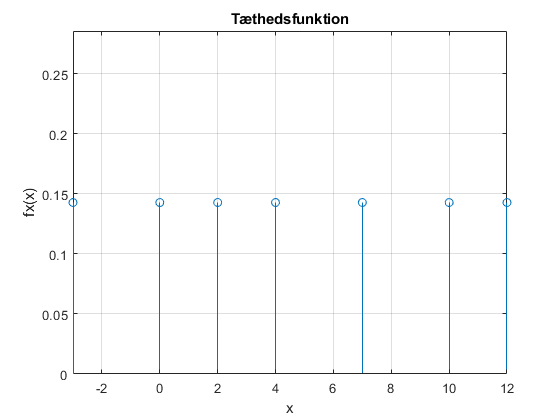

k = 1/7;

X = [-3, 0, 2, 4, 7, 10, 12];
P = [k, k, k, k, k, k, k];

figure(1)
stem(X, P, 'o');
grid on
title('Tæthedsfunktion')
ylabel('fx(x)')
xlabel('x')
xlim([-3 12])
ylim([0 k*2])

### FORVENTNINGSVÆRDI OG VARIANS

For at bestemme forventningsværdien og variansen ud fra $F_X \left(x\right)$ anvendes at der for forventningsværdien gælder, at


$$\bar{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$


EstimationX = 0;

for n = 1:length(P)
    EstimationX = EstimationX + (X(n) * P(n));
end

EstimationX

EstimationX = 4.5714

For variansen gælder der, at


$$\mathrm{Var}\left(X\right)=\sigma_x^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


EstimationXSquared = 0;

for n = 1:length(P)
    EstimationXSquared = EstimationXSquared + (X(n)^2 * P(n));
end

VarianceX = EstimationXSquared - EstimationX^2

VarianceX = 25.1020

Variansen er dermed bestemt til at være 25.1.

### SANDSYNLIGHEDER

For at bestemme $P\left(x\ge 2\right)$samt $P\left(x>2\right)$ anvendes, at arealet for en tæthedsfunktion er lig med 1, hvormed


$$\sum_{i=1}^n f_X \left(x_i \right)=\sum_{i=1}^n P\left(X=x_i \right)=1$$


Samtidig antages, at $k=\frac{1}{7}$.

fx = @(x) k;

ProbabilityEqualOrAbove = sym(fx(2) + fx(4) + fx(7) + fx(10) + fx(12))

$$ProbabilityEqualOrAbove = \frac{5}{7}$$

Dermed er $P\left(x\ge 2\right)$bestemt til at være $\frac{5}{7}$.

fx = @(x) k;

ProbabilityAbove = sym(fx(4) + fx(7) + fx(10) + fx(12))

$$ProbabilityAbove = \frac{4}{7}$$

Dermed er $P\left(x>2\right)$ bestemt til at være $\frac{4}{7}$.

### FORDELINGSFUNKTION

For at bestemme fordelingsfunktionen for $X$anvendes, at 


$$F_x \left(x\right)=\sum_{x_i \le x}^n f_x \left(x_i \right)=P\left(X\le x\right)$$


Hvor det for eksempler af mellemregninger giver, at


$$F_x \left(-3\right)=$$

$$\sum_{x_i \le -3}^n f_x \left(-3\right)=f_x \left(-3\right)=\frac{1}{7}$$



$$F_x \left(0\right)=$$

$$\sum_{x_i \le 0}^n f_x \left(0\right)=f_x \left(-3\right)+f_x \left(0\right)=\frac{2}{7}$$


$F_x \left(2\right)=$$\sum_{x_i \le 2}^n f_x \left(2\right)=f_x \left(-3\right)+f_x \left(0\right)+f_x \left(2\right)=\frac{3}{7}$...

Hvor $k$antages at være $\frac{1}{7}$, hvilket dermed giver, at


$$F_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & x<-3\\
k & -3\le x<0\\
2k & 0\le x<2\\
3k & 2\le x<4\\
4k & 4\le x<7\\
5k & 7\le x<10\\
6k & 10\le x<12\\
7k & x\ge 12
\end{array}\right\rbrack \right\rbrace$$


## **FORÅR 2017**

En diskret stokastisk variabel $X$har følgende fordelingsfunktion $F_X \left(x\right)$.

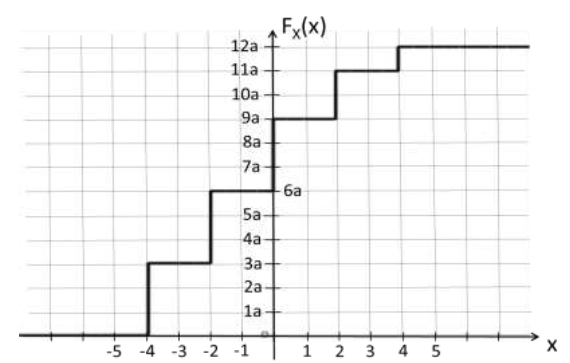

### GYLDIG FORDELINGSFUNKTION

For at bestemme om $F_{X\left(x\right)}$er en gyldig fordeligsfunktion anvendes, at 


$$\underset{x\to \infty }{\mathrm{lim}} F_X \left(x\right)=1$$


Det antages at outputtet af fordelingsfunktione ikke antager værdier større end 12a, der gælder følgende.


$$\underset{x\to \infty }{\mathrm{lim}} F_X \left(x\right)=12a$$


Dermed givet det, at


$$a=\frac{1}{12}$$


Fordelingsfunktionen er dermed gældende for værdien af $a$ leg med $\frac{1}{12}$.

### TÆTHEDSFUNKTION

For at bestemme tæthedsfunktione $f_X \left(x\right)$anvendes, at størrelse af trinene i fordelingsfunktion er tæthedsfunktionen. Dermed opnåes, at


$$f_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
3a & x=-4\\
3a & x=-2\\
3a & x=0\\
2a & x=2\\
1a & x=4\\
0 & \mathrm{ellers}
\end{array}\right\rbrack \right\rbrace$$


### MIDDELVÆRDI

For at bestemme middelværdien anvendes, at


$$\bar{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$


a = 1/12;

X = [-4, -2, 0, 2, 4];
P = [3*a, 3*a, 3*a, 2*a, 1*a];

EstimationX = 0;

for n = 1:length(P)
    EstimationX = EstimationX + (X(n) * P(n));
end

sym(EstimationX)

$$ans = -\frac{5}{6}$$

Middelværdien er dermed bestemt til at være $-\frac{5}{6}\ldotp$

### VARIANS

For at bestemme variansen anvendes, at


$$\mathrm{Var}\left(X\right)=\sigma_x^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


EstimationXSquared = 0;

for n = 1:length(P)
    EstimationXSquared = EstimationXSquared + (X(n)^2 * P(n));
end

VarianceX = EstimationXSquared - EstimationX^2

VarianceX = 6.3056

Variansen er dermed bestemt til at være 6.3056.

## **FORÅR 2017 REEKSAMEN**

En kontinuert stokastisk variabel $X$har følgende fordelingsfunktion $F_X \left(x\right)$.

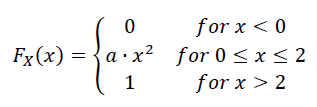

### GYLDIG FORDELINGSFUNKTION

For at bestemme om $F_X \left(x\right)$ er en gyldig fordelingsfunktion anvendes, at for $x>2$ er $F_X \left(x\right)=1$, hvormed 


$$a\cdot x^2 =1,\;\mathrm{hvor}\;\;x=2$$


syms Fx(x) a
Fx(x) = piecewise(x<0, 0, (0<=x) & (x<=2), a*x^2, x>2, 1);

Eq = int(diff(Fx(x)), -inf, inf) == 1

$$Eq = 4\,a=1$$

solve(Eq, a)

$$ans = \frac{1}{4}$$

 $F_X \left(x\right)$ er en gyldig tæthedsfunktione for værdien af $a$ lig med $\frac{1}{4}\ldotp$

### TÆTHEDSFUNKTION

For at finde tæthedsfunktionen anvendes, at


$$f_X \left(x\right)=\frac{\textrm{d}}{\textrm{d}x}F_X \left(x\right)$$


syms Fx(x)
a = 1/4;
Fx(x) = piecewise(x<0, 0, (0<=x) & (x<=2), a*x^2, x>2, 1)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<0\\ \frac{x^{2}}{4} & \text{ if }x\in \left[0,2\right]\\ 1 & \text{ if }2<x \end{array}\right.$$

Tæthedsfunktionen $f_X \left(x\right)$hermed bestemt til at være


$$f_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & x<0\\
2a\cdot x=\frac{1}{2}x & 0\le x\le 2\\
0 & x>2
\end{array}\right\rbrack \right\rbrace$$


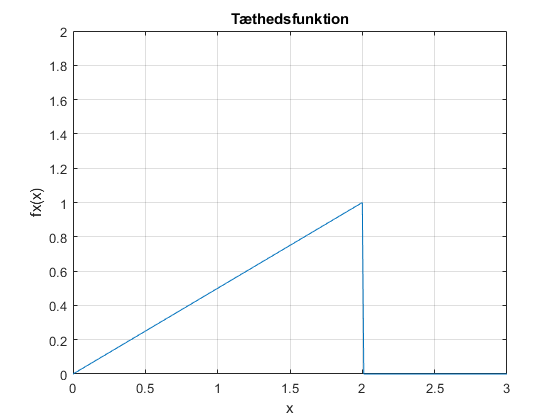

syms fx(x) 
fx(x) = piecewise(x<0, 0, (0<=x) & (x<=2), 1/2*x, x>2, 0);
x = 0:0.01:3;

figure(1)
plot(x, fx(x));
grid on
title('Tæthedsfunktion')
ylabel('fx(x)')
xlabel('x')
axis([0, 3, 0, 2]);

### SANDSYNLIGHED 

For at bestemme sandsynligheden for $1\le X\le 2$ anvendes, at


$$P\left(a\le X\le b\right)=\int_a^b f_X \left(x\right)\mathrm{dx}$$


Da $f_X \left(x\right)$ i intervallet fra 1 til 2 er lig med $\frac{1}{2}x$, vides at


$$\int_1^2 f_X \left(x\right)\mathrm{dx}$$


clear x
xpdf = @(x) 1/2*x;

integral(xpdf, 1, 2)

ans = 0.7500

Sandsynligheden er dermed bestemt til at være 0.75 altså 75%.

### MIDDELVÆRDI OG VARIANS

For at bestemme forvetningsværdien anvendes, at 


$$E\left\lbrack X\right\rbrack =\bar{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}=\int_0^2 x\cdot \frac{1}{2}\cdot x\;\mathrm{dx}$$


hvor værdien for $a$ antages, at være $\frac{1}{4}$.

a = 1/4;
xpdf = @(x) x .* 1/2.*x;
EstimationValue = sym(integral(xpdf, 0, 2))

$$EstimationValue = \frac{4}{3}$$

Forventningsværdien er dermed bestemt til, at være $\frac{4}{3}$. Variansen bestemmes dernæst ved følgende,


$$\mathrm{Var}\left(x\right)=\int_{-\infty }^{\infty } \left(x-\bar{x} \right)\cdot f_X \left(x\right)\mathrm{dx}=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


fx = @(x) x.^2 * 1/2.*x;
Variance = sym(integral(fx, 0, 2)) - EstimationValue^2

$$Variance = \frac{2}{9}$$

Variansen er dermed bestemt til, at være $\frac{2}{9}$.

## **FORÅR 2018**

En tæthedsfunktion for en stokastisk variabel er defineret til at være 

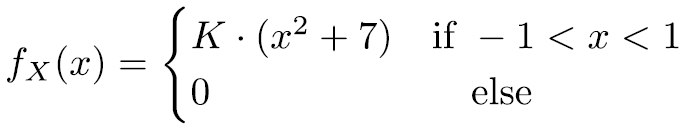

## 2.1 GYLDIG TÆTHEDSFUNKTION

For en gyldig tæthedsfunktion gælder, at


$$\int_{-\infty }^{\infty } f_X \left(x\right)\mathrm{dx}=1$$


Hvor $k$ kan isoleres og beregnes som følgende i matlab.

syms fx(x) k
fx(x) = piecewise(-1<x<1, k*(x^2 + 7), 0);
k = solve(int(fx(x), -inf, inf) == 1, k)

$$k = \frac{3}{44}$$

Dermed er $k$ bestemt til at være lig med $\frac{3}{44}$ for at $f_X \left(x\right)$er en gyldig tæthedsfunktion.

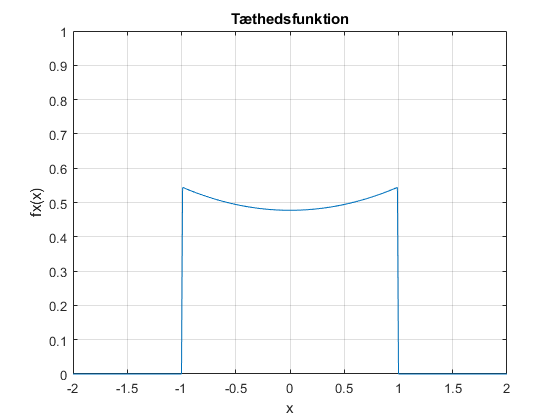

syms fx(x) 
fx(x) = piecewise(-1<x<1, (3/44)*(x^2 + 7), 0);
x = -2:0.01:2;

figure(1)
plot(x, fx(x));
grid on
title('Tæthedsfunktion')
ylabel('fx(x)')
xlabel('x')
axis([-2, 2, 0, 1]);

## 2.2 MIDDELVÆRDI

For at bestemme middelværiden anvendes, at


$$\bar{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$



$$E\left\lbrack X\right\rbrack =\bar{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}$$


syms xfx(x) 
xfx(x) = piecewise(-1<x<1, x*((3/44)*(x^2 + 7)), 0);

MeanValue = int(xfx(x), -inf, inf)

$$MeanValue = 0$$

Dermed middelværiden bestemt til at være 0.

## 2.3 VARIANS

For at bestemme standard afvigelsen benyttes, at


$$\mathrm{Var}\left(x\right)=\sigma^2 =\int_{-\infty }^{\infty } \left(x-\bar{x} \right)\cdot f_X \left(x\right)\mathrm{dx}=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$



$$\sigma =\sqrt{\sigma^2 }$$


syms xfx(x) 
xfx(x) = piecewise(-1<x<1, x^2*((3/44)*(x^2 + 7)), 0);

MeanSquareValue = int(xfx(x), -inf, inf);

Variance = MeanSquareValue - MeanValue^2;
StandardDeviation = sqrt(Variance)

$$StandardDeviation = \frac{\sqrt{19}\,\sqrt{55}}{55}$$

(sqrt(19)*sqrt(55)) / 55

ans = 0.5878

Standard afvigelsen er dermed bestemt til at være 0.5878.

## 2.4 FORDELINGSFUNKTION

For at finde fordelingsfunktionen anvendes, at


$$F_X \left(x\right)=\int_{-\infty }^x f_X \left(x\right)\mathrm{dx}$$


syms fx(x) k
fx(x) = piecewise(-1<x<1, (3/44)*(x^2 + 7), 0);

int(fx(x), -inf, x)

$$ans = \left\{ \begin{array}{cl} 1 & \text{ if }1\leq x\\ 0 & \text{ if }x\leq -1\\ \frac{x^{3}}{44}+\frac{21\,x}{44}+\frac{1}{2} & \text{ if }x\in \left(-1,1\right] \end{array}\right.$$

## **FORÅR 2018 REEKSAMEN**

# **STOKASTISKE PROCESSER**

## **EFTERÅR 2015**

En diskret process er givet ved X(n) = w(n), w(n) angives desuden til at være i.i.d efter en uniform fordeling med w(n) ~ U(0, 10).

### SKITSERING AF REALISATION

Skitser 10 samples af en realisation af processen X(n) for n = 1.. 10.

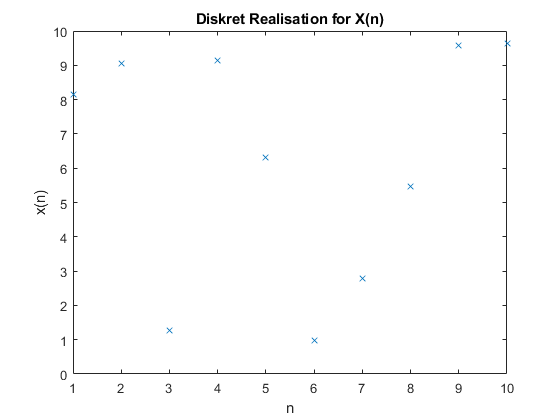

mu = 0;
sigma = 10;

realisation = sigma * rand(1, 10) + mu;

figure(1)
plot(1:length(realisation), realisation, 'x');
title('Diskret Realisation for X(n)')
xlabel('n')
ylabel('x(n)')

### MIDDELVÆRDI OG VARIANS

Bestem ensemble middelværdien og variansen for processen X(n).


$$E\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack w\left(n\right)\right\rbrack$$


da processen er uniform fordelt gælder følgende for $w=\;\mu \left(a,b\right)$


$$E\left\lbrack X\left(n\right)\right\rbrack =\frac{a+b}{2}$$


Som omskrevet bliver til


$$E\left\lbrack X\left(n\right)\right\rbrack =\frac{1}{2}\left(a+b\right)$$


ensembleMean = (1/2) * (mu + sigma);

disp("Ensemble middelværdien for processen er " + ensembleMean);

Ensemble middelværdien for processen er 5


for variansen af en uniform fordeling gælder følgende for $w=\;\mu \left(a,b\right)$

   
$$\mathrm{var}\left(w\right)=\frac{1}{12}{\left(b-a\right)}^2$$


ensembleVariance = (1/12) * (sigma - mu)^2;

disp("Ensemble variansen for processen er " + ensembleVariance);

Ensemble variansen for processen er 8.3333


sym(ensembleVariance)

$$ans = \frac{25}{3}$$

### AUTOKORRELATION

Bestem autokorrelationsfunktionen Rxx(t) for processen X(n) for t = 0.. 3.

For korrelationen til n = 0 gælder der, at


$$R_{\mathrm{XX}} \left(n\right)=E\left\lbrack X\left(n\right)\cdot X\left(n\right)\right\rbrack$$


Da der for variansen gældet, at 


$$\mathrm{var}\left(X\right)=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$
 

Kan korrelation omskrives til følgende


$$R_{\mathrm{XX}} \left(n\right)=\mathrm{var}\left(X\right)+E{\left\lbrack X\right\rbrack }^2$$


n = 0;

correlation(n + 1) = ensembleVariance + ensembleMean^2;

Hvor der for autokorrelationen til n > 0 gælder, at


$$R_{\mathrm{XX}} \left(n\right)=E\left\lbrack X\left(n\right)\cdot X\left(n+1\right)\right\rbrack ,\;n>1$$


Kan omskrives til

   
$$R_{\mathrm{XX}} \left(n\right)=E\left\lbrack X\left(n\right)\right\rbrack \cdot E\left\lbrack X\left(n+1\right)\right\rbrack$$


da processen er uniform fordelt gælder følgende for $w=\;\mu \left(a,b\right)$


$$E\left\lbrack X\left(n\right)\right\rbrack =\frac{a+b}{2}$$


således bliver det til følgende


$$R_{\mathrm{XX}} \left(n\right)=\left(\frac{a+b}{2}\right)\cdot \left(\frac{a+b}{2}\right)={\left(\frac{a+b}{2}\right)}^2$$


w(n) og w(n + 1) er uafhængige grundet i.i.d.

for n = 1:3
    correlation(n + 1) = ((mu + sigma) / 2)^2;
end

correlation = sym(correlation)

$$correlation = \left(\begin{array}{cccc} \frac{100}{3} & 25 & 25 & 25 \end{array}\right)$$

### PROCESSEN

Angiv om processen er WSS (stationær i den bredde forstand) og om den er ergodisk**.**

Da middelværdien $E\left\lbrack X\left(n\right)\right\rbrack$er uafhængig af n og konstant samt variancen er uafhængig af n og konstant, kan processen siges at være stationær i den bredde forstand.Samtidig er processen ergodisk da den ikke er tidsahængig samt middelværdien og variansen for ensemble ikke ændres. Disse værdier kan opnås ved en enkelt realisering og vil for flere realiseringer være den samme.

## **EFTERÅR 2015 REEKSAMEN**

En diskret stokastisk process er givet ved


$$X\left(n\right)=w\left(n\right)+4$$


Hvor hver sample n af w er i.i.d Gaussisk fordelte stokastiske variable w(n) ~ N(0,1).

### **SKITSERING AF REALISATION**

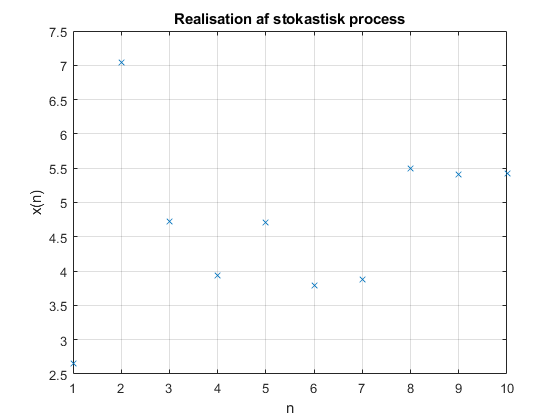

mu = 0;
sigma = 1;

realisation = (sigma * randn(1, 10) + mu) + 4;

figure(1)
plot(1:length(realisation), realisation, 'x');
title('Realisation af stokastisk process');
xlabel('n')
ylabel('x(n)')
grid on

### MIDDELVÆRDI OG VARIANS


$$E\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack w\left(n\right)+4\right\rbrack$$



$$E\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack w\left(n\right)\right\rbrack +E\left\lbrack 4\right\rbrack$$


Ensemble.Mean = mu + 4;

disp("Ensemble middelværdien er: " + Ensemble.Mean);

Ensemble middelværdien er: 4



$$\mathrm{var}\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack {X\left(n\right)}^2 \right\rbrack -E{\left\lbrack X\left(n\right)\right\rbrack }^2$$



$$\mathrm{var}\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack {w\left(n\right)}^2 \right\rbrack +E\left\lbrack 4^2 \right\rbrack -4^2$$



$$\mathrm{var}\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack {w\left(n\right)}^2 \right\rbrack =\mathrm{var}\left(w\left(n\right)\right)=1$$


Ensemble.Variance = 1;

disp("Ensemble variansen er : "+ Ensemble.Variance);

Ensemble variansen er : 1


### PROCESSEN

Processen er wide state stationary da middelværdien og varians ikke er tidsafhængige. Processen er ergodisk, da middelværdi og varians kan bestemmes ud fra en realisation.

## **EFTERÅR 2016**

En kontinuær stokastisk process er givet ved


$$X\left(t\right)=w\left(t\right)$$


Hvor $w\left(t\right)$ er i.i.d uniformt fordelt efter $w\left(t\right)~U\left(-2,-1\right)$.

### SKITSERING AF SAMPLES

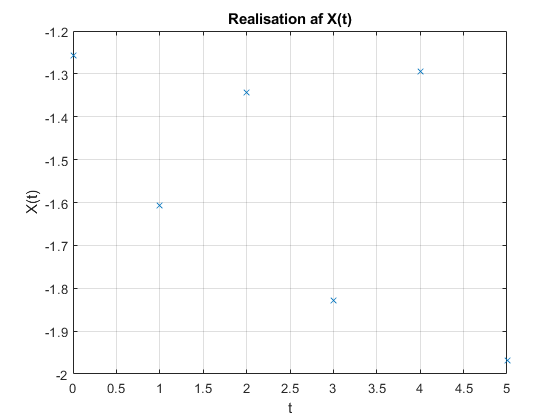

a = -2;
b = -1;

Realisation = rand(1,6) + a;
Time = 0:1:5;

figure(2)
plot(Time, Realisation, 'x');
grid on
title('Realisation af X(t)');
ylabel('X(t)');
xlabel('t');

### ENSEMBLE MIDDELVÆRDI OG VARIANS

Middelværdien for ensemblen kan bestemms som


$$E\left\lbrack X\left(t\right)\right\rbrack =\int_{-\infty }^{\infty } x\left(t\right)\cdot f_{X\left(t\right)} \left(x\left(t\right)\right)\mathrm{dx}\left(t\right)$$


hvor $f_{X\left(t\right)} \left(x\left(t\right)\right)$er tæthedsfunktionenfor processen $x\left(t\right)$til tiden $t$. Da $x\left(t\right)=w\left(t\right)$$\mathrm{og}\;w\left(t\right)~U\left(-2,-1\right)$


$$E\left\lbrack X\left(t\right)\right\rbrack =\int_a^b w\left(t\right)\cdot 1\;\mathrm{dw}={\left\lbrack \frac{1}{2}w^{2\;} \right\rbrack }_{-2}^{-1} =\frac{-3}{2}$$


Integration af en uniform fordeling tæthedsfunktion er arealet hvilket er lig med 1.

f = @(w) w.*1;

ensemble.expectation = round(integral(f, a, b), 10);

disp("Forventningsværdien er bestemt til at være " + ensemble.expectation);

Forventningsværdien er bestemt til at være -1.5


f = @(w) (w.^2).*1;

ensemble.expectationsquared = round(integral(f, a, b), 10);

disp("Variansen er bestemt til at være: " + (ensemble.expectationsquared - ensemble.expectation^2));

Variansen er bestemt til at være: 0.083333


### TIDSLIGE MIDDELVÆRDI

Formlen for den tidslige middelværdi er som følgende.


$${\left\langle \mu_x \right\rangle }_t =\frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} x\left(t\right)\mathrm{dt}$$


### PROCESSEN

Processen x(t) er stationær i den bredde forstand da ensemble middelværdi og varians ikke er tidsafhængige. Processen er ergodisk da ensemble tæthedsfunktionen kan findes ud fra en realisation.

## **EFTERÅR 2016 REEKSAMEN**

En diskret stokastisk process er givet for den n'te ved


$$X\left(n\right)=w\left(n\right)+0\ldotp 7$$


Hvor w(n) er i.i.d fordelte efter den angivet tabel.

### SKITSERING AF SAMPLES

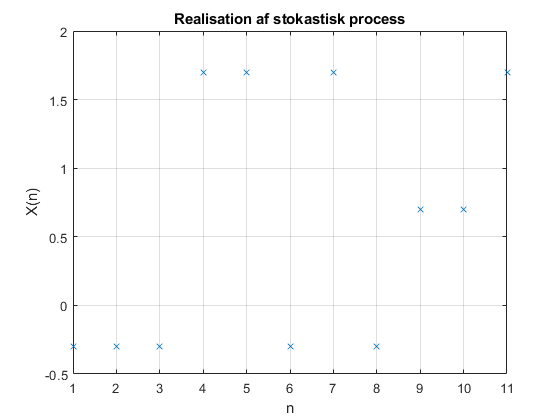

n = 0:10;

realisation = unidrnd(3, 1, 11) - 2 + 0.7;

figure(1)
plot(1:length(realisation), realisation, 'x');
title('Realisation af stokastisk process');
xlabel('n')
ylabel('X(n)')
grid on

### MIDDELVÆRDI OG VARIANS


$$E\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack w\left(n\right)+0\ldotp 7\right\rbrack$$



$$E\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack w\left(n\right)\right\rbrack +0\ldotp 7$$



$$E\left\lbrack w\left(n\right)\right\rbrack =\sum_w w\left(n\right)\cdot f_{w\left(n\right)} \left(w\left(n\right)\right)$$


ExpectationValueW = -1 * (1/3) + 0 * (1/3) + 1 * (1/3);

MeanValue = ExpectationValueW + 0.7;

disp("Ensemble middelværdien er bestemt til at være " + MeanValue);

Ensemble middelværdien er bestemt til at være 0.7


For variansen gælder, at 


$$\sigma_{x\left(n\right)}^2 =E\left\lbrack {X\left(n\right)}^2 \right\rbrack -E{\left\lbrack X\left(n\right)\right\rbrack }^2 =E\left\lbrack {\left(w\left(n\right)+0\ldotp 7\right)}^2 \right\rbrack -E{\left\lbrack w\left(n\right)+0\ldotp 7\right\rbrack }^2$$



$$\sigma_{x\left(n\right)}^2 =E\left\lbrack {w\left(n\right)}^2 \right\rbrack -E{\left\lbrack w\left(n\right)\right\rbrack }^2 =E\left\lbrack {w\left(n\right)}^2 \right\rbrack$$


Variance = (-1)^2 * (1/3) + 0^2 * (1/3) + 1^2 * (1/3);

disp("Ensemble variansen er bestemt til at være " + Variance);

Ensemble variansen er bestemt til at være 0.66667


### AUTOKORRELATION

Formlen til at bestemme autokorrelationen for $X\left(n\right)$er som følgende.


$$R_{\mathrm{XX}} \left(\tau \right)=\sum_n x\left(n\right)\cdot x\left(n-\tau \right)\cdot f_x \left(x\right)$$


hvor $f_x \left(x\right)=f_w \left(w+0\ldotp 7\right)$.

### PROCESSEN

Processen er wss da middelværdien og autokorrelationen ikke er tidsafhængige. Processen er ergodisk da pmf kan bestemmes ud fra en realisation.

## **EFTERÅR 2017**

En stokastisk process er givet ved

$X\left(n\right)=\alpha \cdot t$ for $t\ge 0$

Hvor $\alpha \sim N\left(1,\frac{1}{4}\right)$.

### REALISATION

En skitsering af den stokastiske process $X\left(t\right)$ i intervallet $t=\left\lbrack 0;10\right\rbrack$ er bestemt som følgende.

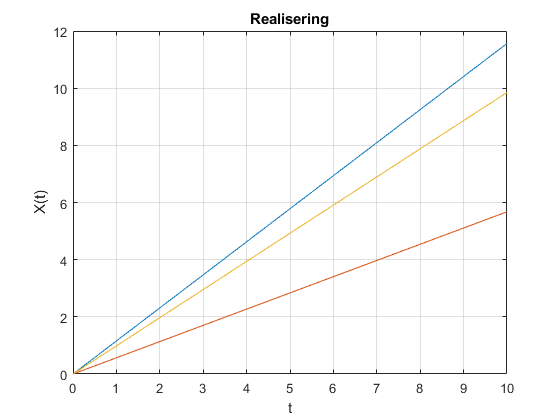

mu = 1;
sigma = sqrt(1/4);
t = 0:1:10;

Realisation = [[],[],[]];

for n = 1:3
   Realisation(n, :) = (ones(1, 11) * (sigma * randn + mu)) .* t;
end 

figure(3)
plot(t, Realisation(1, :));
hold on
plot(t, Realisation(2, :));
plot(t, Realisation(3, :));
grid on
title('Realisering')
ylabel('X(t)')
xlabel('t')
hold off

### ENSEMBLE

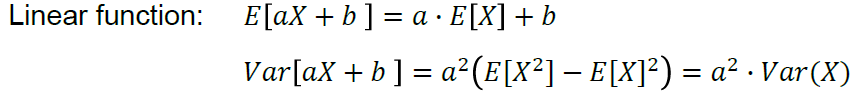

Da forventningsværdien til alpha, som er normaltfordelt, er lig med 1 kan middelværdien bestemmes som


$$E\left\lbrack X\right\rbrack =E\left\lbrack \alpha \cdot t\right\rbrack =E\left\lbrack \alpha \right\rbrack \cdot t=1\cdot t=t$$


Dertil er også anvendt at $X\left(t\right)$er en lineær funktion, hvilket også betyder at variansen kan bestemmes som følgende.


$$\mathrm{Var}\left\lbrack X\right\rbrack =\mathrm{Var}\left\lbrack \alpha \cdot t\right\rbrack =t^2 \cdot \mathrm{Var}\left(\alpha \right)=\frac{1}{4}t^2$$


### PROCESSEN

Den stokastiske process er ikke WSS da både ensemble mean og ensemble variansen er afhængig af tiden.

Da processen ikke er WSS er den heller ikke ergodisk.

## **EFTERÅR 2018**

En diskret stokastisk process $X\left\lbrack n\right\rbrack$er givet ved


$$X\left\lbrack n\right\rbrack =2\cdot Y\left\lbrack n\right\rbrack +W$$


Hvor 


$$Y\left\lbrack n\right\rbrack \sim N\left(5,\;2\right)$$


Samt


$$W\sim U\left(-2,\;2\right)$$


Som er kontinuært uniform fordelt. Det antages, at $Y$ og $W$er uafhængige.

### REALISERING

Realiseringen er lavet i matlab.

Y = sqrt(2) * randn(1, 11) + 5;
W = 2 * rand - 2;
X = 2 * Y + W;

n = linspace(0, 10, 11);

figure(2)
plot(n, X, 'x', 'Color', Color.DeepCleret);
grid on
title('Realisering af X(n)')
axis([0, 10, 0, 20])
ylabel('X(n)')
xlabel('n')

### ENSEMBLE

For at bestemme middelværdien anvendes, at


$$E\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack 2\cdot Y+W\right\rbrack$$



$$E\left\lbrack X\left(n\right)\right\rbrack =2\cdot E\left\lbrack Y\right\rbrack +E\left\lbrack W\right\rbrack$$


hvor 

$E\left\lbrack W\right\rbrack =\mu =\frac{a+b}{2}$, $\;\;U\left(a,b\right)$


$$E\left\lbrack W\right\rbrack =\frac{-2+2}{2}=0$$


Samt


$$E\left\lbrack Y\right\rbrack =5,\;\;N\left(5,2\right)$$


Dermed kan det bestemmes at middelværdien er som følgende


$$E\left\lbrack X\right\rbrack =2\cdot 5+0=10$$


For at bestemme variansen anvendes, at


$$\mathrm{Var}\left\lbrack \mathrm{aX}+b\right\rbrack =a^2 \cdot \mathrm{Var}\left(X\right)$$


Hvormed der i dette tilfælde gælder, at 


$$\mathrm{Var}\left\lbrack X\right\rbrack =\mathrm{Var}\left\lbrack 2\cdot Y+W\right\rbrack$$



$$\mathrm{Var}\left\lbrack X\right\rbrack =\mathrm{Var}\left\lbrack 2\cdot Y\right\rbrack +\mathrm{Var}\left\lbrack W\right\rbrack$$



$$\mathrm{Var}\left\lbrack X\right\rbrack =2^2 \cdot \mathrm{Var}\left\lbrack Y\right\rbrack +\mathrm{Var}\left\lbrack W\right\rbrack$$


hvor variansen til $Y$findes ved normalfordelingen som er opgivet og bestemt til 2 og variansen for $W$bestemmes for en uniform fordeling ved følgende udtryk.


$$\mathrm{Var}\left\lbrack W\right\rbrack =\sigma^2 =\frac{1}{12}{\left(b-a\right)}^2$$


EnsembleVariance = 2^2 * 2 + (1/12 * (2 - (-2))^2)

Variansen er dermed bestemt til at være 9.3333.

### PROCESSEN

Processen er stationær i den bredde forstand da middelværdien og variansen er konstant og uafhængig af tid. Da $W$er forskellig for de enkelte realisationer er processen ikke ergodisk.

## **FORÅR 2016**

En kontinuer stokastisk process er givet ved


$$X\left(t\right)=w+4$$


Hvor $w$ er normalfordelt efter $N\left(5,1\right)$.

### REALISERING

For at skitsere en realisering af den kontinuere process vides det, at


$$\sigma^2 =1,\mu =5$$


Dertil kan realiseringen laves ved brug af matlab.

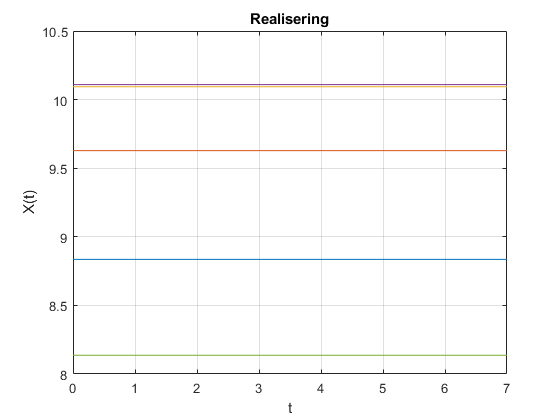

t = 0:1:7;
mu = 5;
sigma = sqrt(1);

Realisation = [[],[],[],[],[]];

for n = 1:5
   Realisation(n, :) = (ones(1, 8) * (sigma * randn + mu)) + 4;
end 

figure(3)
plot(t, Realisation(1, :));
hold on
plot(t, Realisation(2, :));
plot(t, Realisation(3, :));
plot(t, Realisation(4, :));
plot(t, Realisation(5, :));
grid on
title('Realisering')
ylabel('X(t)')
xlabel('t')
hold off

### MIDDELVÆRDI OG VARIANS

For at bestemme middelværdien for ensemble anvendes, at


$$E\left\lbrack X\left(t\right)\right\rbrack =E\left\lbrack w+4\right\rbrack =E\left\lbrack w\right\rbrack +E\left\lbrack 4\right\rbrack$$


Ensemble.MeanValue = mu + 4;

Variansen kan bestemmes som


$$\mathrm{Var}\left(X\left(t\right)\right)=\mathrm{Var}\left\lbrack w+4\right\rbrack =\mathrm{Var}\left\lbrack w\right\rbrack +\mathrm{Var}\left\lbrack 4\right\rbrack$$


Ensemble.Variance = sigma^2 + 0;

Ensemble

Ensemble = struct with fields:
         Mean: 4
     Variance: 1
    MeanValue: 9


Dermed er middelværdien bestemt til at være 9 og variansen bestemt til at være 1.

### REALISERINGS MIDDELVÆRDI OG VARIANS

Real.Mean = mean(Realisation(1, :));
Real.Variance = round(var(Realisation(1, :)), 10);

Real

Real = struct with fields:
        Mean: 8.8351
    Variance: 0


Middelværdi og variansen for en udvalgt realisering er bestemt til at være værdierne vist ovenfor.

### PROCESSEN

Da ensemble middelværdi og varianse er uafhængig af tiden og samtidig konstant er processen WSS. Processen er ikke ergodisk da middelværdien og variansen af en realisering ikke siger noget om en middelværdi og varians for hele processen.

## **FORÅR 2016 REEKSAMEN**

En kontinuer stokastisk process er givet ved


$$X\left(t\right)=w\left(t\right)$$


Hvor $w\left(t\right)$er i.i.d (uafhængig og ens fordelt) og normalfordelt efter $w\left(t\right)\sim N\left(t,1\right)$.

### REALISERING

Realiseringen laves ved brug af matlab.

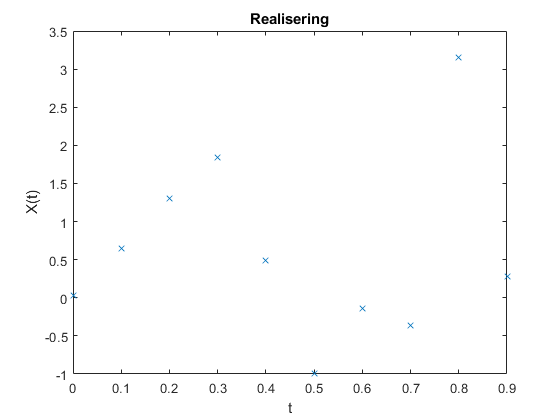

t = 0:0.1:0.9;

mu = t;
sigma = sqrt(1);

Realisation = randn(1, length(t)) + t;

figure(2)
plot(t, Realisation(1, :), 'x');
title('Realisering')
ylabel('X(t)')
xlabel('t')
hold off

### ENSEMBLE

For at bestemme middelværdien for ensemble anvendes, at


$$E\left\lbrack X\left(t\right)\right\rbrack =E\left\lbrack w\left(t\right)\right\rbrack =t$$


Ensemble.MeanValue = t;

Variansen kan bestemmes som


$$\mathrm{Var}\left(X\left(t\right)\right)=\mathrm{Var}\left\lbrack w\left(t\right)\right\rbrack =1$$


Ensemble.Variance = sigma^2;

Ensemble

Ensemble = struct with fields:
         Mean: 4
     Variance: 1
    MeanValue: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000]


Dermed er middelværdien bestemt til at være $t$ og variansen bestemt til at være 1.

### TEMPORAL MEAN

Den tidslige middelværdi kan bestemmes som


$$\mu_{X\left(t\right)} \left(t\right)=E\left\lbrack X\left(t\right)\right\rbrack =\int_{-\infty }^{\infty } x\left(t\right)f_{X\left(t\right)} \left(x\left(t\right)\right)\mathrm{dx}\left(t\right)$$


Hvor den forventede tidslige middelværdi i en intervallet kan bestemmes som gennemsnittet i intervallet bestem som følgende.


$$\frac{1}{n}\cdot \int_0^{100} E\left\lbrack X\left(t\right)\right\rbrack \mathrm{dt}$$


t = 0:1:100;

TemporalMeanEstimate = sum(t) / length(t)

TemporalMeanEstimate = 50

### PROCESSEN

Da middelværiden er afhængig af tiden er processen ikke WSS. Da processen ikke er WSS kan processen heller ikke være ergodisk.

### AUTOKORRELATION

Ligningen til at bestemme autokorrelationen er som følgende


$$R_{x\left(t_1 \right)x\left(t_2 \right)} \left(t_1 =1,t_2 =2\right)=\int_{x\left(t_1 \right)}^{\ldotp } \int_{x\left(t_2 \right)}^{\ldotp } x\left(t_1 \right)x\left(t_2 \right)\cdot f_{X\left(t_1 \right),X\left(t_2 \right)} \left(x\left(t_1 \right),x\left(t_2 \right)\right)\;\mathrm{dx}\left(t_1 \right)\mathrm{dx}\left(t_2 \right)$$


Da $x\left(t_1 \right)$ og $x\left(t_2 \right)$er uafhængige gælder, at


$$R_{x\left(t_1 \right)x\left(t_2 \right)} \left(t_1 =1,t_2 =2\right)=E\left\lbrack x\left(t_1 \right)\right\rbrack \cdot E\left\lbrack x\left(t_2 \right)\right\rbrack$$


Rx = @(x, y) t(x + 1) * t(y + 1);

AutoCorrelationValue = Rx(1, 2)

AutoCorrelationValue = 2

Værdien for autokorrelation er dermed bestemt til at være 2.

## **FORÅR 2017**

En kontinuert stokastisk process $X\left(t\right)$givet ved


$$X\left(t\right)={\left(-1\right)}^n +W$$


hvor W er i.i.d. Gaussisk fordelte stokastiske variable W ~ N(0, 0.25) og n uafhængigt kan antage værdierne 0 og 1 med lige stor sandsynlighed.�(0; 0,25), og n uafhængigt kan . 

###  REALISERING

Skitsering af realiseringen laves i matlab.

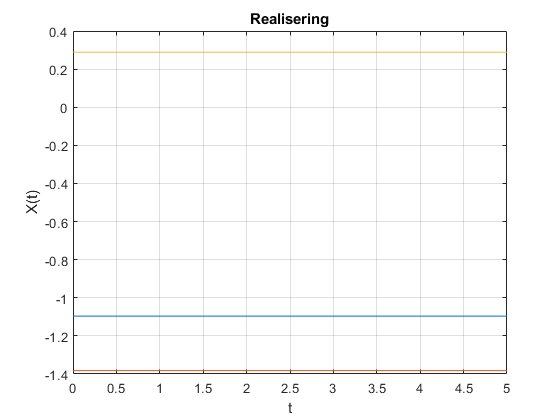

t = 0:1:5;

mu = 0;
sigma = sqrt(0.25);

Realisation = [[],[],[]];


for n = 1:3
    Realisation(n, :) = (-1)^(randi([0, 1])) + (ones(1, length(t)) * (sigma * randn + mu));
end

figure(1)
plot(t, Realisation(1, :));
hold on
plot(t, Realisation(2, :));
plot(t, Realisation(3, :));
grid on
title('Realisering')
ylabel('X(t)')
xlabel('t')
hold off

### MIDDEL OG VARIANS AF REALISERING

Real.Mean = mean(Realisation(1, :));
Real.Variance = round(var(Realisation(1, :)), 10);

Real

Real = struct with fields:
        Mean: -1.0962
    Variance: 0


Middelværdi og variansen for en udvalgt realisering er bestemt til at være værdierne vist ovenfor.

### ENSEMBLE MIDDELVÆRDI OG VARIANS

For at bestemme middelværdien for ensemble anvendes, at


$$E\left\lbrack X\left(t\right)\right\rbrack =E\left\lbrack {\left(-1\right)}^n +W\right\rbrack =E\left\lbrack {\left(-1\right)}^n \right\rbrack +E\left\lbrack W\right\rbrack$$



$$E\left\lbrack X\left(t\right)\right\rbrack ={\left(-1\right)}^0 \cdot P\left(n=0\right)+{\left(-1\right)}^1 \cdot P\left(n=1\right)+E\left\lbrack W\right\rbrack$$



$$P\left(n=0\right)=P\left(n=1\right)=\frac{1}{2}$$


Ensemble.MeanValue = ((-1)^0) * 1/2 + ((-1)^1) * 1/2 + mu;

Variansen kan bestemmes som


$$\mathrm{Var}\left(X\left(t\right)\right)=\mathrm{Var}\left\lbrack {\left(-1\right)}^n +W\right\rbrack =\mathrm{Var}\left\lbrack {\left(-1\right)}^n \right\rbrack +\mathrm{Var}\left\lbrack W\right\rbrack$$



$$\mathrm{Var}\left\lbrack X\left(t\right)\right\rbrack =E\left\lbrack {\left({\left(-1\right)}^n \right)}^2 \right\rbrack -E{\left\lbrack {\left(-1\right)}^n \right\rbrack }^2 +\mathrm{Var}\left\lbrack W\right\rbrack$$


Ensemble.Variance = (((-1)^0)^2 * 1/2 + ((-1)^1)^2 * 1/2) ...
    + (((-1)^0) * 1/2 + ((-1)^1) * 1/2)^2 + sigma^2;

Ensemble

Ensemble = struct with fields:
         Mean: 4
     Variance: 1.2500
    MeanValue: 0


Dermed er middelværdien bestemt til at være 0 og variansen bestemt til at være 1.25.

### PROCESSEN

Processen er WSS da middelværdien og variansen er uafhængig af tiden. Dog er processen ikke ergodisk da den temporale middelværdi samt varians er forskellige fra ensemble værdierne.

## **FORÅR 2017 REEKSAMEN**

En diskret stokastisk process $X\left(n\right)$er givet ved


$$X\left(n\right)=2\cdot W\left(n\right)-1$$


hvor $W\left(n\right)$ er i.i.d fordelte efter

### REALISERING

Realisering af den diskrete process er lavet i Matlab.

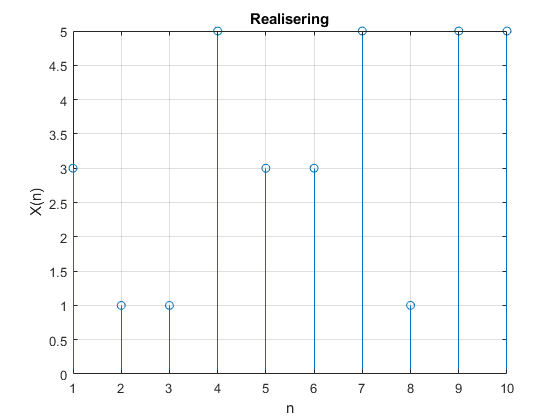

X = 2 * (unidrnd(4, 1, 10) - 1) - 1;
n = 1:1:10;

figure(1)
stem(n, X, 'o');
grid on
title('Realisering')
ylabel('X(n)')
xlabel('n')
hold off

### REALISERING MIDDELVÆRDI OG VARIANS

Real.Mean = mean(X);
Real.Variance = round(var(X), 10);

Real

Real = struct with fields:
        Mean: 3.2000
    Variance: 3.0667


### MIDDELVÆRDI OG VARIANS

For at bestemme middelværdien for processen anvendes, at 


$$E\left(\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack 2\cdot W\left(n\right)-1\right\rbrack =2\cdot E\left\lbrack W\left(n\right)\right\rbrack -1\right.$$


Hvor $W\left(n\right)$er uniform og dermed gælder, at 


$$E\left\lbrack W\left(n\right)\right\rbrack =\frac{a+b}{2}$$


hvor $a=0$ og $b=3$

a = 0;
b = 3;

MeanValue = 2 * ((a+b)/2) - 1

MeanValue = 2

Middelværdien er dermed bestemt til at være 2. For variansen gælder, at


$$\mathrm{Var}\left\lbrack X\left(n\right)\right\rbrack =\mathrm{Var}\left\lbrack 2\cdot W\left(n\right)-1\right\rbrack =2^2 \cdot \mathrm{Var}\left\lbrack W\left(n\right)\right\rbrack$$



$$\mathrm{Var}\left\lbrack W\left(n\right)\right\rbrack =\frac{1}{12}{\left(b-a\right)}^2$$


Variance = 2^2 * ((1/12)*((b-a+1)^2 - 1))

Variance = 5

### PROCESSEN

Processen er WSS da middelværdi og varians er uafhængig af tiden. Da Middelværdi og varians kan bestemmes ud fra en realisering er processen ergodisk.

## **FORÅR 2018**

En kontinuert stokastisk process er givet ved


$$y\left(t\right)=x\left(t\right)+w$$


hvor $x\left(t\right)\sim N\left(0,t^2 \right)$og $w\sim N\left(3,1\right)$. x og w er uafhængige.

### REALISERING

Realiseringen af lavet i matlab.

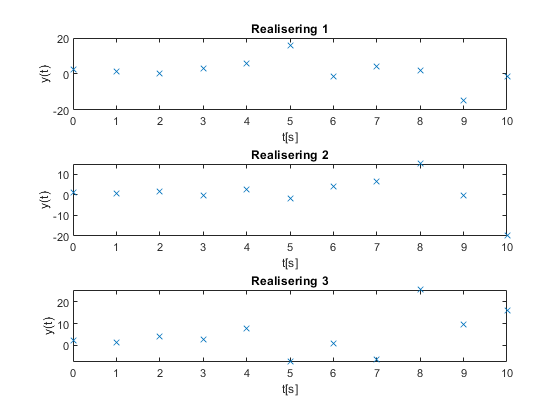

t = 0:1:10;


nmu = 3;
nvariance = 1;

xmu = 0;
xvariance = t.^2;

y = [[],[],[]];

for n = 1:3
    w = sqrt(nvariance) * randn + nmu;
    x = sqrt(xvariance) .* randn(1, 11) + xmu;    
    y(n, :) = x + w;
end

figure(2)
subplot(3,1,1,gca)
plot(t, y(1, :), 'x');
title('Realisering 1');
xlabel('t[s]');
ylabel('y(t)');

subplot(3,1,2)
plot(t, y(2, :), 'x');
title('Realisering 2');
xlabel('t[s]');
ylabel('y(t)');

subplot(3,1,3)
plot(t, y(3, :), 'x');
title('Realisering 3');
xlabel('t[s]');
ylabel('y(t)');
hold off

### ENSEMBLE MIDDELVÆRDI

For at bestemme middelværiden anvendes, at


$$E\left\lbrack y\left(t\right)\right\rbrack =E\left\lbrack x\left(t\right)+w\right\rbrack =E\left\lbrack x\left(t\right)\right\rbrack +E\left\lbrack w\right\rbrack$$


EnsembleMean = xmu + nmu

EnsembleMean = 3

Middelværdien for ensemble er dermed bestemt til at være 3.

## 3.3 ENSEMBLE VARIANS

For at bestemme variansen anvendes, at


$$\mathrm{Var}\left\lbrack y\left(t\right)\right\rbrack =\mathrm{Var}\left(x\left(t\right)+w\right)=\mathrm{Var}\left\lbrack x\left(t\right)\right\rbrack +\mathrm{Var}\left\lbrack w\right\rbrack$$


syms t
EnsembleVariance = t^2 + nvariance

$$EnsembleVariance = t^{2}+1$$

Variansen for ensemble er dermed bestemt til at være $t^2 +1$.

### TIDSLIG MIDDELVÆRDI

For at bestemme den tidslige middelværdi og varians for en realisation af processen kan følgende anvendes.


$$\hat{\mu_{X_i } } =\left\langle X_i \right\rangle =\underset{T\to \infty }{\mathrm{lim}} \frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} x_i \left(t\right)\mathrm{dt}$$



$$\hat{\sigma_{X_i }^2 } ={\left\langle X_i^2 \right\rangle }_T -{\left\langle X_i \right\rangle }_T^2 =\underset{T\to \infty }{\mathrm{lim}} \frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} \left(x_i {\left(t\right)}^2 -{\hat{\mu_{X_i } } }^2 \right)\mathrm{dt}$$


For middelværdien gælder, at


$$\hat{\mu_{Y_1 } } =\underset{N\to \infty }{\mathrm{lim}} \frac{1}{N}\sum_{n=0}^N \left(y_1 \left(n\cdot T\right)\right)=\underset{N\to \infty }{\mathrm{lim}} \frac{1}{N}\sum_{n=0}^N \left(x_1 \left(n\right)+w_1 \right)=0+w_1 =w_1$$


For variansen gælder, at


$${\hat{\sigma_{Y_1 } } }^2 =\lim_{N\to \infty } \frac{1}{N}\sum_{n=0}^N \left(y_1^2 \left(n\cdot T\right)-{\hat{\mu_{Y_1 } } }^2 \right)=\underset{N\to \infty }{\mathrm{lim}} \frac{1}{N}\sum_{n=0}^N {\left(x_1 \left(n\right)+w_1 \right)}^2 -w_1^2 =\infty =\left(t^2 \right)$$


### PROCESSEN

Da den tidslige varians er forskellige fra ensemble varians er processen ikke WSS. Da processen ikke er WSS er processen heller ikke ergodisk.

## **FORÅR 2018 REEKSAMEN**

# **SANDSYNLIGHED**

## **EFTERÅR 2015**

### **TOTAL SANDSYNLIGHED**

**Event A: Laktoseintolerent**

**Event B: Positiv Test**

$P\left(A\right)=0\ldotp 2$,  $P\left(B|A\right)=0\ldotp 9$,  $P\left(B|\overline{A} \right)=0\ldotp 3$

Den totale sandsynlighed kan findes udtryk som følgende: 


$$P\left(B\right)=\sum_{i=1}^n P\left(B\;|\;A_i \right)\cdot P\left(A_i \right)$$


Intolerant = 0.2;
IntolerantPositiveTest = 0.9;
NoIntolerantPositiveTest = 0.3;
NotIntolerant = 1 - Intolerant;

PositiveTest = (IntolerantPositiveTest * Intolerant) + (NoIntolerantPositiveTest * NotIntolerant)

PositiveTest = 0.4200

Sandsynligheden er dermed bestemt til at være 0.42 altså 42%.

### BETINGET SANDSYNLIGHED

For at finde sandsynligheden for at have en positiv test same også at have sygdommen kan findes ved at anvende bayes formel som nedenstående: 


$$P\left(A|B\right)=\frac{P\left(B|A\right)\cdot P\left(A\right)}{P\left(B\right)}$$


IntolerantGivenPositiveTest = (IntolerantPositiveTest * Intolerant) / PositiveTest

IntolerantGivenPositiveTest = 0.4286

Sandsynligheden er dermed bestemt til at være 0.4286 altså 42.86%.

## **EFTERÅR 2015 REEKSAMEN**

### **RELATIVE FREKVENS**

**EVENT A: HJERTER KONGE**

**EVENT B: SPAR ES**

Sandsynligheden for at trækker hjerte konge blandt de syv kort er som følgende. Der vil være syv muligheder blandt de allerede trukket kort for at finde en hjerter konge.

Cards = 52;
Drawings = 7;

A = Drawings / Cards

A = 0.1346

Sandsynligheden er dermed 0.1346 altså 13.46%.

### FÆLLESMÆNGDE


$$P\left(B\right)=P\left(A\right)=0\ldotp 13462$$



$$P\left(A\cap B\right)=P\left(A|B\right)\cdot P\left(B\right)$$


B = Drawings / Cards;

AGivenB = (Drawings - 1) / (Cards - 1);

AAndB = AGivenB * B

AAndB = 0.0158

Sandsynligheden er dermed 0.0158 altså 1.58%.

### UAFHÆNGIGHED

For at tjekke om der er uafhængig gælder følgende udtryk for uafhængighed


$$P\left(A\right)\cdot P\left(B\right)=P\left(A\cap B\right)$$


if A * B == AAndB
    disp("A og B er uafhængige");
else
    disp("A og B er ikke uafhængige");
end

A og B er ikke uafhængige


Det er dermed bestemt at de to hændelser A og B ikke er uafhængige.

### KOMBINATIONER

Det antages at eksperimentet ikke er i orden og er uden tilbagelægning, derved gælder, at (k objects out of collection of n objects)


$$\left(\frac{n}{k}\right)=\frac{n!}{k!\left(n-k\right)!}$$


n = 52;
k = 7;

Combinations = factorial(n) / (factorial(k) * factorial(n-k))

Combinations = 133784560

Dermed er antallet af kombinationer bestemt til at være 133784560.

## **EFTERÅR 2016**

### **FÆLLESMÆNGDE**


$$P\left(B|A\right)=0\ldotp 92,\;\;P\left(\overline{B} |\overline{A} \right)=0\ldotp 98,\;P\left(A\right)=0\ldotp 001$$



$$P\left(B\cap A\right)=P\left(B\left|A\right.\right)\cdot P\left(A\right)$$


BGivenA = 0.92;
NotBGivenNotA = 0.98;
A = 0.001;

AAndB = BGivenA * A

AAndB = 9.2000e-04

Sandsynligheden er dermed bestemt til at være 0.00092 altså 0.092%.

### **BETINGET SANDSYNLIGHED**

Der anvendes, at


$$P\left(B\right)=P\left(B|A\right)\cdot P\left(A\right)+P\left(B|\overline{A} \right)\cdot P\left(\overline{A} \right)$$



$$P\left(\overline{A} \right)=1-P\left(A\right)$$



$$P\left(B|\overline{A} \right)=1-P\left(\overline{B} |\overline{A} \right)$$


NotA = 1 - A;
B = AAndB + ((1 - NotBGivenNotA) * NotA)

B = 0.0209

Sandsynligheden er dermed bestemt til at være 0.0209 altså 2.09%.

### BETINGET SANDSYNLIGHED

Der anvendes, at


$$P\left(A|B\right)=\frac{P\left(A\cap B\right)}{P\left(B\right)}$$


AGivenB = AAndB / B

AGivenB = 0.0440

Sandsynligheden er dermed bestemt til at være 0.0440 altså 4.40%.

### UAFHÆNGIGHED

if A * B == AAndB
    disp("A og B er uafhængige");
else
    disp("A og B er ikke uafhængige");
end

A og B er ikke uafhængige


Det er dermed bestemt at de to hændelser A og B ikke er uafhængige.

## **EFTERÅR 2016 REEKSAMEN**

### VENN DIAGRAM

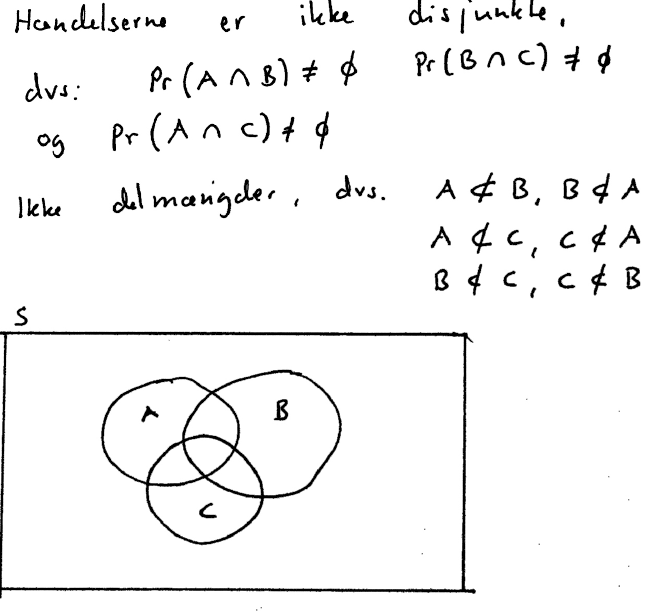

### FÆLLESMÆNGDE

Find sandsynligheden for, at der både er blade på skinnerne og signalfejl.


$$P\left(A\cap B\right)=P\left(A|B\right)\cdot P\left(B\right)$$


da begivenhederne er uafhængige ses følgende


$$P\left(A|B\right)=P\left(A\right)$$


hvorved


$$P\left(A\cap B\right)=P\left(A\right)\cdot P\left(B\right)$$


A = 1/4;
B = 1/2;
C = 1/4;

LeavesAndSignal = A * B

LeavesAndSignal = 0.1250

Sandsynligheden er dermed bestemt til at være 0.1250 altså 12.5%.

### FORENINGSMÆNGDE

Find sandsynligheden for, at der enten er blade på skinnerne eller signalfejl.


$$P\left(A\cup B\right)=P\left(A\right)+P\left(B\right)-P\left(A\cap B\right)$$


LeavesOrSignal = A + B - LeavesAndSignal

LeavesOrSignal = 0.6250

Sandsynligheden er dermed bestemt til at være 0.6250 altså 62.5%.

### SAMLET FORENINGSMÆNGDE

Find sandsynligheden for, at en forsinkelse på toget skyldes blade på skinnerne, signalfejl eller personalemangel.


$$P\left(A\cup B\cup C\right)=P\left(A\right)+P\left(B\right)+P\left(C\right)-P\left(A\cap B\right)-P\left(A\cap C\right)-P\left(B\cap C\right)+P\left(A\cap B\cap C\right)$$


da A, B og C er uafhængige gælder, at


$$P\left(A\cup B\cup C\right)=P\left(A\right)+P\left(B\right)+P\left(C\right)-P\left(A\right)\cdot P\left(B\right)-P\left(A\right)\cdot P\left(C\right)-P\left(B\right)\cdot P\left(C\right)+P\left(A\right)\cdot P\left(B\right)\cdot P\left(C\right)$$


LeavesSignalPersonal = A + B + C - (A * B) - (A * C) - (B * C) + (A * B * C)

LeavesSignalPersonal = 0.7188

Sansynligheden er dermed bestemt til at være 0.7188 altså 71.88%.

## **EFTERÅR 2017**

### MARGINALE MASSEFUNKTION

For de marginale tæthedsfunktioner gælder, at

$f_X \left(x\right)=\sum_y f_{X,Y} \left(x,y\right)$, $\;\;\;f_Y \left(y\right)=\sum_x f_{X,Y} \left(x,y\right)$

Der gælder, at 


$$\sum_{x=1}^4 \sum_{y=1}^3 f_{X,Y} \left(x,y\right)=1$$


BatEgg = [2/25, 2/25, 1/25, 1/25];
BarnEgg = [2/25, 3/25, 3/25, 2/25];
EcoEgg = [1/25, 2/25, 3/25, 0];

EcoEgg(4) = 1 - (sum(BatEgg) + sum(BarnEgg) + sum(EcoEgg));

disp("Sandsynligheden for et økoæg af størrelsen 4 er " + EcoEgg(4));

Sandsynligheden for et økoæg af størrelsen 4 er 0.12


### MARGINALE MASSEFUNKTION

Sandsynligheden for at et tilfældigt æg er af størrelsen 3, kan findes ved følgende udtryk.


$$f_X \left(x=3\right)=\sum_y f_{X,Y} \left(x=3,y\right)$$


Egg = [
        [2/25, 2/25, 1/25, 1/25]
        [2/25, 3/25, 3/25, 2/25] 
        [1/25, 2/25, 3/25, 3/25]
];

SizeThree = sum(Egg(:,3));

disp("Sandsynligheden for et tilfædigt æg med størrelse 3 er lig med " + SizeThree);

Sandsynligheden for et tilfædigt æg med størrelse 3 er lig med 0.28


### MARGINALE MASSEFUNKTION

Sandsynligheden for at et tilfældigt æg er et buræg, kan findes ved følgende udtryk.


$$f_Y \left(y=1\right)=\sum_x f_{X,Y} \left(x,y=1\right)$$


BatEgg = sum(Egg(1, :));

disp("Sandsynligheden for et tilfældigt buræg er lig med " + BatEgg);

Sandsynligheden for et tilfældigt buræg er lig med 0.24


### BETINGET MASSEFUNKTION

Sandsynligheden for at det tilfældige udtagne æg er et skrabeæg givet,

at det er af størrelsen 2 kan beregnes ud fra følgende udtryk.


$$f_{Y|X} \left(y|x\right)=\frac{f_{X,Y} \left(x,y\right)}{f_X \left(x\right)}=P\left(Y=y,X=x\right)$$


hvor x = 2 og y er = 2.

BarnEggGivenSizeTwo = Egg(2, 2) / sum(Egg(:, 2));

disp("Sandsynligheden for at ægget er et" + ...
    " skrabeæg givet at størrelsen er 2, er lig med " + BarnEggGivenSizeTwo);

Sandsynligheden for at ægget er et skrabeæg givet at størrelsen er 2, er lig med 0.42857


## **EFTERÅR 2018**

### **TOTAL SANDSYNLIGHED**

For at bestemme I hvor stor en del af situationerne der var alarm opstilles to hændelse givet ved A og B som følgende.

***A : ALARM***

***B : RØG***


$$P\left(B\right)=0\ldotp 33$$



$$P\left(A\cap B\right)=0\ldotp 32$$



$$P\left(A\cap \overline{B} \right)=0\ldotp 07$$
 

B = 0.33;
AAndB = 0.32;
ANotB = 0.07;

Dertil anvendes den totale sandsynlighed for A som er giver ved


$$P\left(A\right)=P\left(A\cap B\right)+P\left(A\cap \overline{B} \right)$$


A = AAndB + ANotB

A = 0.3900

Dette betyder, at der i 39% af tilfældene var alarm.

### BETINGET SANDSYNLIGHED

For at bestemme sandsynligheden for situationer uden røgudvikling, at der alligevel vil være alarm anvendes følgende.


$$P\left(A|\overline{B} \right)=\frac{P\left(A\cap \overline{B} \right)}{P\left(\overline{B} \right)}$$



$$P\left(\overline{B} \right)=1-P\left(B\right)$$


NotB = 1 - B;
AGivenNotB = ANotB / NotB

AGivenNotB = 0.1045

Dette betyder, at der i 10.45% af tilfældene uden røgudvikling vil være alarm.

### BETINGET SANDSYNLIGHED

For at bestemme sandsynligheden for situationer med røgudvikling, at der ikke vil være alarm anvendes følgende.


$$P\left(\overline{A} |B\right)=1-P\left(A|B\right)=\frac{P\left(A\cap B\right)}{P\left(B\right)}$$


NotAGivenB = 1 - (AAndB / B)

NotAGivenB = 0.0303

Dette betyder, at der i 3% af tilfældene med røgudvikling ikke vil være alarm.

## **FORÅR 2016**

### RELATIVE FREKVENS

For at bestemme hvad sandsynligheden er for hændelse A, vides det, at der blev født 29.785 drenge og 28.131 piger i 2012. Da anvendes den relative frekvens som er bestemt ved følgende udtryk.


$$P\left(A\right)=\frac{N_A }{N}=\frac{28\ldotp 131}{28\ldotp 131+29\ldotp 785}$$


Boys = 29785;
Girls = 28131;

A = Girls / (Girls + Boys)

A = 0.4857

Sandsynligheden for hændelse **A** er dermed bestemt til at være 48.57%.

### TOTAL SANDSYNLIGHED

Den totale sandsynlighed for hændelse **C** kan bestemmes ved, at anvende følgende.


$$P\left(A\right)=P\left(A\cap B\right)+P\left(A\cap \overline{B} \right)$$



$$P\left(A\right)=P\left(A|B\right)\cdot P\left(B\right)+P\left(A|\overline{B} \right)\cdot P\left(\overline{B} \right)$$


Der antages i dette tilfælde for opgaven, at $P\left(B\right)=1-P\left(A\right)$ da den modsatte hændelse at at få en pige vil være at få en dreng.

B = 1 - A;
CGivenB = 0.202;
CGivenA = 0.128;

C = CGivenA * A + CGivenB * B

C = 0.1661

Den totale sandsynlighed for hændelse **C** er dermed bestemt til at være 16.61%.

### BETINGET SANDSYNLIGHED

For at bestemme hvad sansynligheden for at den fødende fik en pige, hvis det oplyses, at hendes barn vejede over 4000g ved fødslen anvendes, at


$$P\left(A|C\right)=\frac{P\left(C|A\right)\cdot P\left(A\right)}{P\left(C\right)}$$


AGivenC = (CGivenA * A) / C

AGivenC = 0.3744

Dermed er sandsynligheden for, at den fødende fik en pige givet at barnet vejde over 4000g ved fødslen, bestemt til at være 37.44%.

## **FORÅR 2016 REEKSAMEN**

### TOTAL SANDSYNLIGHED

Den totale sandsynlighed for hændelse **B** kan bestemmes ved, at anvende følgende.


$$P\left(B\right)=P\left(B\cap A\right)+P\left(B\cap \bar{A} \right)$$



$$P\left(B\right)=P\left(B\left|A\right.\right)\cdot P\left(A\right)+P\left(B\left|\bar{A} \right.\right)\cdot P\left(\bar{A} \right)$$


BGivenA = 0.06;
BGivenNotA = 0.03;
A = 0.31;

NotA = 1 - A;

B = BGivenA * A + BGivenNotA * NotA

B = 0.0393

Sandsynligheden for hændelse B er dermed bestemt til at være 0.0393 altså 3.93%.

### BETINGET SANDSYNLIGHED

For at bestemme sandsynligheden for om et barn tilhørte gruppen der havde flyttet mere end en gang, hvis det havde begået kriminalitet anvendes, at


$$P\left(A|B\right)=\frac{P\left(B|A\right)\cdot P\left(A\right)}{P\left(B\right)}$$


AGivenB = (BGivenA * A) / B

AGivenB = 0.4733

Sandsynligheden er dermed bestemt til at være 0.4733 altså 47.33%.

## **FORÅR 2017**

### **TOTAL SANDSYNLIGHED**

Først findes den totale sandsynlighed for A, givet ved


$$P\left(A\right)=P\left(A|B\right)\cdot P\left(B\right)+P\left(A|\overline{B} \right)\cdot P\left(\overline{B} \right)$$


DaysInMonth = 30;

AGivenB = 0.2;
AGivenNotB = 0.3;
B = 0.5;

NotB = 0.5;

A = AGivenB * B + AGivenNotB * NotB;
DaysWithRain = A * 30

DaysWithRain = 7.5000

Dermed er det bestemt at der regner i gennemsnit 7.5 i juni måned.

### BETINGET SANDSYNLIGHED

For at bestemme sandsynligheden for at være i den sidste del af måneden givet at der er regnvejr anvendes, at


$$P\left(\overline{B} |A\right)=\frac{P\left(A|\overline{B} \right)\cdot P\left(\overline{B} \right)}{P\left(A\right)}$$


NotBGivenA = (AGivenNotB * B) / A

NotBGivenA = 0.6000

Dermed er sandsynligheden bestemt til at være 0.6 altså 60%.

### KOMBINATORIK

For at bestemme sandsynligheden for højst en dag med regnes observeres, at 


$$P\left(\mathrm{dage}\le 1|B\right)=P\left(0\;\mathrm{dage}\;|\;B\right)+P\left(1\;\mathrm{dag}|B\right)$$


Dertil anvendes ikke sorteret rækkefølge uden tilbagelægning. Succes ses som


$$P\left(A|B\right)=p=0\ldotp 2$$


hvor fiasko ses som 


$$P\left(\overline{A} |B\right)=1-p=0\ldotp 8$$


Sandsynligheden kan bestemmes som 


$$P\left(k\right)=\frac{n!}{k!\cdot \left(n-k\right)!}p^k q^{{\;}^{n-k} }$$


DaysWithinHalfMonth = DaysInMonth / 2;

Bernoulli = @(k, n) (factorial(n) / (factorial(k) * factorial(n-k))) * (AGivenB^k) * ((1-AGivenB)^(n-k));

Bernoulli(1, 15) + Bernoulli(0, 15)

ans = 0.1671

Dermed er sandsynligheden for regn højst en dag bestemt til at være 0.1671 altså 16.71%.

## **FORÅR 2017 REEKSAMEN**

En leverance af modstande indeholder

Modstandene leveres både som 5% modstande og 1% modstande. 1% modstandene udgør ¼ af 1 kΩ, ½ af 10 kΩ og ¾ af 100 kΩ modstandene. Modstandene er desværre blevet blandet sammen og leveres i én blandet pose.


$$A_1 :1k\Omega$$
  
$$A_{10} :10k\Omega$$
   
$$A_{100} :100k\Omega$$



$$B_1 :1%$$
   
$$B_5 :5%$$



$$P\left(B_1 |A_1 \right)=\frac{1}{4}$$



$$P\left(B_1 |A_{10} \right)=\frac{1}{2}$$



$$P\left({B_1 |A}_{100} \right)=\frac{3}{4}$$


BOneGivenAOne = 1/4;
BOneGivenATen = 1/2;
BOneGivenAHundred = 3/4;

ROne = 1000;
RTen = 800;
RHundred = 400;

Resistors = ROne + RTen + RHundred;

### RELATIVE FREKVENS

For at bestemme sandsynlighede for hvilken modstand der trækkes anvendes, at


$$P\left(A\right)=\frac{N_s }{N}$$


Resistor.One = ROne / Resistors;
Resistor.Ten = RTen / Resistors;
Resistor.Hundred = RHundred / Resistors;

Resistor

Resistor = struct with fields:
        One: 0.4545
        Ten: 0.3636
    Hundred: 0.1818


Sandsynligheden for at trække hhv. 1, 10 eller 100 kilohms modstand er vist i ovenstående.

### FÆLLESMÆNGDE

For at bestemme sandsynligheden for, at modstanden er både $10k\Omega$ og 1% anvendes, at


$$P\left(A_{10} \cap B_1 \right)=P\left(B_1 |A_{10} \right)\cdot P\left(A_{10} \right)$$


ATenAndBOne = BOneGivenATen * Resistor.Ten

ATenAndBOne = 0.1818

Sandsynligheden er dermed bestemt til at være 0.1818 altså 18.18%.

### TOTAL SANDSYNLIGHED

For at bestemme sandsynligheden for at den udtagne modstand er 1% anvendes, at


$$P\left(A\right)=\sum_{i=1}^n P\left(A|B_i \right)\cdot P\left(B_i \right)$$


BOne = BOneGivenAOne * Resistor.One + BOneGivenATen * Resistor.Ten + BOneGivenAHundred * Resistor.Hundred

BOne = 0.4318

Sandsynligheden er dermed bestemt til at være 0.4318 altså 43.18%.

### BETINGET SANDSYNLIGHED

For at bestemme sandsynligheden for at modstanden er $100k\Omega$ givet at den er 5% anvendes, at


$$P\left(A_{100} |B_5 \right)=\frac{P\left(B_5 |A_{100} \right)\cdot P\left(A_{100} \right)}{P\left(B_5 \right)}$$


BFive = 1 - BOne;
BFiveGivenAHundred = 1 - BOneGivenAHundred;

AHundredGivenFive = (BFiveGivenAHundred * Resistor.Hundred) / BFive

AHundredGivenFive = 0.0800

Sandsynligheden er dermed bestemt til at være 0.08 altså 8.00%.

## **FORÅR 2018**

Et system er udviklet til at registrere om RFID tags er defekte. En undersøgelse viser, at givet et RFID tag ikke er defekt, er sandsynligheden for, at systemet registrerer, at det ikke er defekt lig med 0.4. Givet et RFID tag er defekt, er sandsynligheden for, at systemet registreret, at det er defekt lig med 0.999. Det vides, at 1 ud af 100 RFID tags er defekte.

A : RFID DEFEKT 

B : REGISTRER DEFEKT


$$P\left(A\right)=\frac{1}{100}$$



$$P\left(\overline{B} |\overline{A} \right)=0\ldotp 4$$



$$P\left(B|A\right)=0\ldotp 999$$


A = 1/100;
NotBGivenNotA = 0.4;
BGivenA = 0.999;

### TOTAL SANDSYNLIGHED

For at bestemme sandsynligheden for at RFID tag ikke er defekt anvendes, at


$$P\left(A\right)=1-P\left(\overline{A} \right)$$


NotA = 1 - A

NotA = 0.9900

Sandsynligheden er dermed bestemt til at være 0.99.

### TOTAL SANDSYNLIGHED

For at bestemme den totale sandsynligheden for at systemet registerer et RFID tag som er defekt anvendes, at


$$P\left(B\right)=P\left(B|A\right)\cdot P\left(A\right)+P\left(B|\overline{A} \right)\cdot P\left(\overline{A} \right)$$



$$P\left(B|\overline{A} \right)=1-P\left(\overline{B} |\overline{A} \right)$$


BGivenNotA = 1 - NotBGivenNotA;

B = BGivenA * A + BGivenNotA * NotA

B = 0.6040

Sandsynligheden er dermed bestemt til at være 0.6040 altså 60.40%.

### BETINGET SANDSYNLIGHED

For at bestemme hvad sandsynligheden for at et RFID tag er defekt givet at det er registreret som defekt anvendes, at


$$P\left(A|B\right)=\frac{P\left(B|A\right)\cdot P\left(A\right)}{P\left(B\right)}$$


AGivenB = (BGivenA * A) / B

AGivenB = 0.0165

Sandsynligheden er dermed bestemt til at være 0.0165 altså 1.65%.

### BETINGET SANDSYNLIGHED

For at bestemme hvad sandsynligheden for at et RFID tag ikke er defekt givet at det er registreret som defekt anvendes, at


$$P\left(\overline{A} |B\right)=\frac{P\left(B|\overline{A} \right)\cdot P\left(\overline{A} \right)}{P\left(B\right)}$$


%NoAGivenB = 1 - AGivenB
NotAGivenB = (BGivenNotA * NotA) / B

NotAGivenB = 0.9835

Sandsynligen er dermed bestemt til at være 0.9835 altså 98.35%.

## **FORÅR 2018 REEKSAMEN**

# **STATISTIK**

## **EFTERÅR 2015**

### **PLOT**

Plot data fra tabellen, og optegn den bedste rette linie gennem punkterne ved at bestemme skæringen med y-aksen og hældningen af den lineære model. Angiv hvilken metode, der er anvendt til at finde den lineære model.

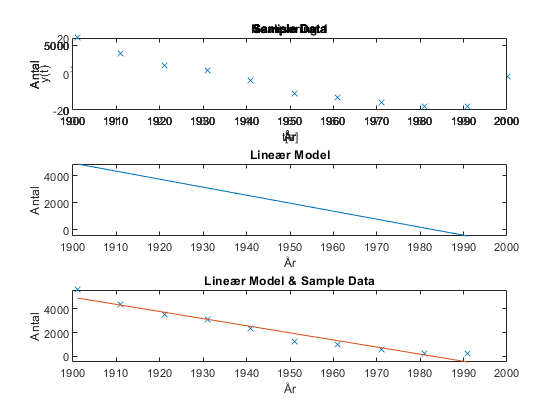

Year = [1901, 1911, 1921, 1931, 1941, 1951, 1961, 1971, 1981, 1991];
Amount = [5562, 4357, 3471, 3078, 2309, 1285, 969, 602, 238, 268];

SampleMean = mean(Amount);
YearMean = mean(Year);


beta = sum((Amount - SampleMean) .* (Year - YearMean)) / sum((Year - YearMean).^2);

alpha = SampleMean - beta * YearMean;

Fitting = beta * Year + alpha;


figure(2)
subplot(3,1,1,gca)
plot(Year, Amount, 'x');
title('Sample Data');
xlabel('År');
ylabel('Antal');

subplot(3,1,2)
plot(Year, Fitting);
title('Lineær Model');
xlabel('År');
ylabel('Antal');

subplot(3,1,3)
plot(Year, Amount, 'x');
hold on
plot(Year, Fitting);
title('Lineær Model & Sample Data');
xlabel('År');
ylabel('Antal');
hold off

### RESIDUAL TEGNING


$$\mathrm{res}\left(t\right)=X\left(t\right)-\left(\alpha +\beta \cdot t\right)$$


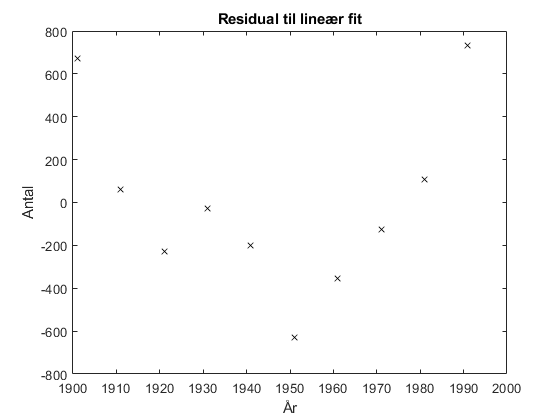

Residuals = Amount - (alpha + beta * Year);

figure(5)
plot(Year, Residuals, 'kx');
title('Residual til lineær fit');
xlabel('År');
ylabel('Antal');

### KONFIDENSINTERVAL

Beregn et 95% konfidensinterval for hældningen.

invers student t fordeling med frihedsgraden n - 2 = 8, og 95% konfidensinterval bestemms $t_0$ til at være som følgende.

Tzero = tinv(0.975, 8);
EmpiricalVariance = (1 / (10 - 2)) * sum((Amount - (alpha + beta * Year)).^2);

interval = Tzero * (sqrt(EmpiricalVariance) / sqrt(sum((Year - YearMean).^2)));

BetaMinus = beta - interval;
BetaPlus = beta + interval;

### LINEARITET

Ud fra svaret i opgave 2 og 3, vil du konkludere at antagelsen om linearitet mellem dødelighed og årstal er rimelig?

Der er umiddelbart for få målepunkter til at kunne konkludere noget generelt. Derimod er der en lineær tendens, men residual plottet viser at residualerne systematisk ligger under 0 mellem år 1920 - 1970, desuden vil data forvente at afvige mere efter år 1991, da dødeligheder ikke kan være negative. Linearitet er ikke en god antagelse.

## **EFTERÅR 2015 REEKSAMEN**

Den gennemsnitlige alder for 1. gangs viede mænd i Danmark er angivet ved følgende tabel


$$\left\lbrack \begin{array}{cccccccccc}
\mathrm{Alder} & 25\ldotp 2 & 26\ldotp 5 & 27\ldotp 9 & 29\ldotp 2 & 30\ldotp 2 & 31\ldotp 7 & 32\ldotp 8 & 34\ldotp 0 & 34\ldotp 3\\
\mathrm{År} & 1971 & 1976 & 1981 & 1986 & 1991 & 1996 & 2001 & 2006 & 2011
\end{array}\right\rbrack$$


### **PLOT DATA**

Til denne opgave anvendes lineær tilnærmelse, hvor


$$\hat{x} =\beta \cdot t+\alpha$$


Dertil anvendes, at 


$$\beta^ˆ =\frac{\sum_{i=1}^n \left(x-\overline{x} \right)\cdot \left(y-\overline{y} \right)}{\sum_{i=1}^n {\left(x-\overline{x} \right)}^2 }$$



$$\alpha^ˆ =\overline{y} -\beta^ˆ \cdot \overline{x}$$


Samt at der for middelværdien gælder, at


$$\overline{x} =\frac{1}{n}\cdot \sum_{i=1}^n x_i$$


Year = [1971, 1976, 1981, 1986, 1991, 1996, 2001, 2006, 2011];
Age = [25.2, 26.5, 27.9, 29.2, 30.2, 31.7, 32.8, 34.0, 34.3];

AgeMean = mean(Age);
YearMean = mean(Year);

beta = sum((Age - AgeMean) .* (Year - YearMean)) / sum((Year - YearMean).^2);
alpha = AgeMean - beta * YearMean;
Fitting = beta * Year + alpha;

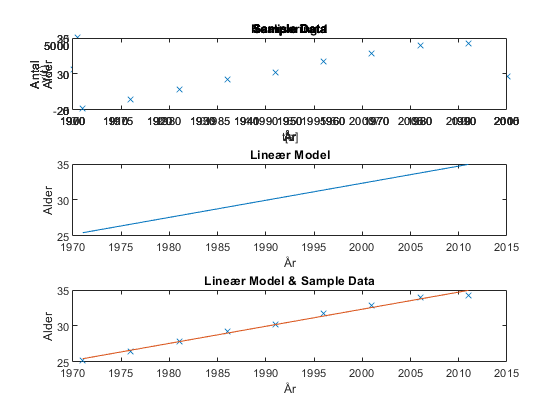

figure(2)
subplot(3,1,1,gca)
plot(Year, Age, 'x');
title('Sample Data');
xlabel('År');
ylabel('Alder');

subplot(3,1,2)
plot(Year, Fitting);
title('Lineær Model');
xlabel('År');
ylabel('Alder');

subplot(3,1,3)
plot(Year, Age, 'x');
hold on
plot(Year, Fitting);
title('Lineær Model & Sample Data');
xlabel('År');
ylabel('Alder');
hold off

### RESIDUALTEGNING

Til at tegne residualer og beregne disse anvendes følgende udtryk.


$$\epsilon_{i\;} =y_i -\left(\alpha +\beta \cdot x_i \right)$$


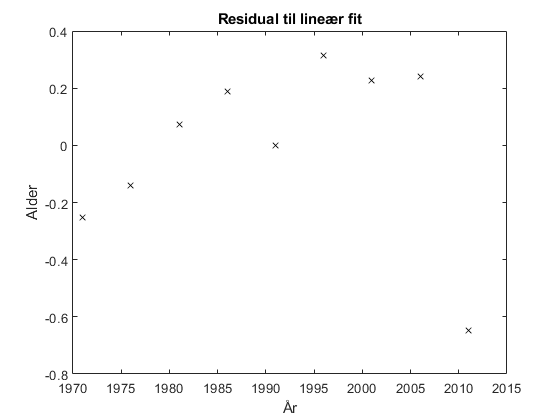

Residuals = Age - (alpha + beta * Year);

figure(6)
plot(Year, Residuals, 'kx');
title('Residual til lineær fit');
xlabel('År');
ylabel('Alder');

### STATISTISK TEST

Da variansen er ukendt og data er gaussiske og ikke parret, benyttes en t-test for sammenligning af middelværdier.

## **EFTERÅR 2016**

Antal patienter døde af AIDS i DK mellem 1985 - 1994 er angivet ved tabellen. Antal døde er angivet ved Antal og årstalet er angivet ved År.

### **MIDDELVÆRDI OG VARIANS**

For middelværdien gælder, at


$$\overline{x} =\frac{1}{n}\cdot \sum_{i=1}^n x_i$$


Amount = [28, 46, 44, 63, 104, 148, 172, 187, 223, 236];
Year = [1985, 1986, 1987, 1988, 1989, 1990, 1991, 1992, 1993, 1994];

AmountMean = mean(Amount);

disp("Middelværdien for antallet af døde AIDS patienter er " + AmountMean);

Middelværdien for antallet af døde AIDS patienter er 125.1


For variansen gælder, at


$${\hat{s} }^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(x_i -\overline{x} \right)}^2$$


n = 10;

variance = (1/(n -1)) * sum((Amount-AmountMean).^2);

disp("Variansen for antaller af døde AIDS patienter er " + variance);

Variansen for antaller af døde AIDS patienter er 6111.4333


### LINEÆR REGRESSION

Til denne opgave anvendes lineær tilnærmelse, hvor


$$\hat{x} =\beta \cdot t+\alpha$$


Dertil anvendes, at 


$$\beta^ˆ =\frac{\sum_{i=1}^n \left(x-\overline{x} \right)\cdot \left(y-\overline{y} \right)}{\sum_{i=1}^n {\left(x-\overline{x} \right)}^2 }$$



$$\alpha^ˆ =\overline{y} -\beta^ˆ \cdot \overline{x}$$


AmountMean = mean(Amount);
YearMean = mean(Year);

beta = sum((Amount - AmountMean) .* (Year - YearMean)) / sum((Year - YearMean).^2);
alpha = AmountMean - beta * YearMean;
Fitting = beta * Year + alpha;

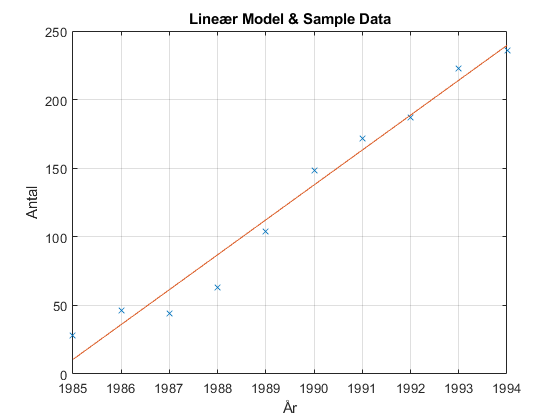

figure(3)
plot(Year, Amount, 'x');
hold on
grid on
plot(Year, Fitting);
title('Lineær Model & Sample Data');
xlabel('År');
ylabel('Antal');
hold off

### RESIDUAL TEGNING

Til at tegne residualer og beregne disse anvendes følgende udtryk.


$$\epsilon_{i\;} =y_i -\left(\alpha +\beta \cdot x_i \right)$$


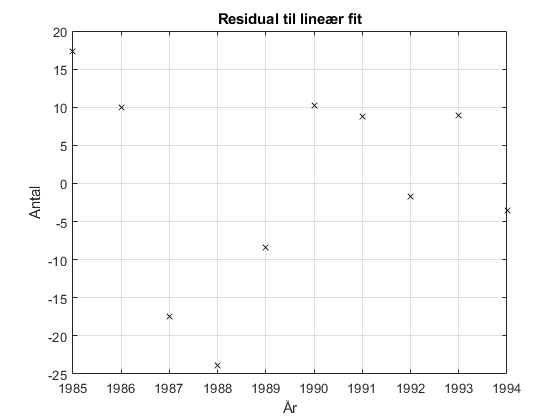

Residuals = Amount - (alpha + beta * Year);

figure(6)
plot(Year, Residuals, 'kx');
grid on
title('Residual til lineær fit');
xlabel('År');
ylabel('Antal');

### KONFIDENSINTERVAL FOR HÆLDNINGEN

invers student t fordeling med frihedsgraden n - 2 = 8, og 95% konfidensinterval bestemms $t_0$ til at være som følgende.

Tzero = tinv(0.975, 8);
EmpiricalVariance = (1 / (10 - 2)) * sum((Amount - (alpha + beta * Year)).^2);

interval = Tzero * (sqrt(EmpiricalVariance) / sqrt(sum((Year - YearMean).^2)));

BetaMinus = beta - interval;
BetaPlus = beta + interval;

disp("Konfidensintervallet for hældningen er b+ = " + BetaPlus + " og b- = " + BetaMinus);

Konfidensintervallet for hældningen er b+ = 29.0544 og b- = 21.8183


### LINEARITET

Set ud fra residual plottet er residualerne fordelt pænt omkring 0. Der er altså ikke et tydeligt mønster. Desuden ligger konfidensintervallet mellem 21.82 og 29.05 og altså tæt på antagelsen om linearitet virker derfor rimelig.

### LINEÆRE MODEL

Modellen kan ikke bruges hvor årstallet er negativ.

## **EFTERÅR 2016 REEKSAMEN**

I et studie af en anerkendt metode til vægttab undersøges 10 patienter før behandling, og ét år efter behandling.

### NULL HYPOTESE

Opstil en null hypotese og alternativ hypotese for at bestemme, om behandlingen har ændret patienternes vægt.

$H_0 :$ forventet vægtændring $\left(\delta \right)=0$

$H_1 :$ forventet vægtændring $\left(\delta \right)\not= 0$

### PARRET EL. UPARRET

Testen bør være parret da det drejer sig om samme patient før og efter behandling. Hvert punkt i datasættet er tilsvarende et punkt i det andet datasæt.

### MIDDEL FORSKELLEN

Estimering af middeforskellen på patienternes vægt før og efter behandling kan findes som.


$$\delta^ˆ =\overline{d} =\frac{1}{n}\sum_{i=1}^n \left(X_{1i} -X_{2i} \right)$$


WeightBefore = [140, 138, 110, 154, 125, 169, 142, 162, 131, 122];
WeightAfter = [130, 121, 127, 101, 92, 170, 143, 170, 134, 85];

MaximumLikelihood = 1/10 * sum(WeightAfter - WeightBefore);

disp("Estimering af middelforskellen af patienternes vægt før og efter behandling er bestemt til at være " + MaximumLikelihood);

Estimering af middelforskellen af patienternes vægt før og efter behandling er bestemt til at være -12


### VARIANS

Sample variansen kan findes som 


$$s_d^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(d_i -\overline{d} \right)}^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(X_{1i} -X_{2i} -\overline{d} \right)}^2$$


SampleVariance = (1/(10-1)) * sum(((WeightAfter - WeightBefore) - MaximumLikelihood).^2);

### T-TEST

Anvendt en parret t-test til hypotesetest. Kan null hypotesen afvises med et signifikansniveau på 0.05?


$$t=\frac{\overline{d} -\delta }{\frac{s_d }{\sqrt{n}}}=\frac{\overline{d} -\delta }{\frac{\sqrt{s_d^2 }}{\sqrt{n}}}$$



$$\mathrm{pvalue}=2\cdot \left(1-t_{\mathrm{cdf}} \left(|t|,n-1\right)\right)$$


t = (MaximumLikelihood - 0) / (sqrt(SampleVariance) / sqrt(10));

pValue = 2 * (1 - tcdf(abs(t), 10-1));

if pValue > 0.05
    disp("Da p-værdien: " + pValue + " er større end 0.05 kan null hypotesen ikke afvises");
else
    disp("Da p-værdien: " + pValue + " er større end 0.05 kan null hypotesen afvises");
end

Da p-værdien: 0.12683 er større end 0.05 kan null hypotesen ikke afvises


### KONFIDENSINTERVAL

For at bestemmes konfidensintervallet anvendes, at


$$\delta_{\pm } =\overline{d} \pm t_0 \cdot \frac{s_d }{\sqrt{n}}$$


TNull = tinv(0.975, 10 -1);

ConfidenceInterval.Plus = MaximumLikelihood + TNull * (sqrt(SampleVariance)/sqrt(10));

ConfidenceInterval.Minus = MaximumLikelihood - TNull * (sqrt(SampleVariance)/sqrt(10));

disp("Konfidensintervallet for vægtforskellen før og efter behandlingen er: " + ConfidenceInterval.Minus + ", " + ConfidenceInterval.Plus);

Konfidensintervallet for vægtforskellen før og efter behandlingen er: -28.1374, 4.1374


## **EFTERÅR 2017**

En nyåbnet webshop forventer, at antallet af ordrer vil være poissonfordelt med et gennemsnit på 25 ordrer i timen.

Tidspunkterne for de enkelte ordrer antages at være uafhængige af hinanden.

### SANDSYNLIGHED EN TIME

For en poission fordeling gælder, at 


$$P\left(X=x\right)=\frac{\gamma^x }{x!}e^{-\gamma }$$


hvor $\gamma =\lambda \cdot t$. Dertil kan sansynligheden for noget mindre eller lig med x findes som


$$P\left(X\le x\right)=\mathrm{poisscdf}\left(x,\gamma \right)$$


altså ved brug af poission fordelingsfunktionen. Da der ønskes en sandsynlighed

for mere end 30 ordrer anvendes, at


$$P\left(X\ge x\right)=1-P\left(X\le x\right)$$


lambda = 25;
hours = 1;
orders = 30;

ProbabilityOverThirty = 1 - poisscdf(orders, hours * lambda);

disp("Sandsynligheden for at der indkommer mere end 30 ordrer på en time er " ... 
    + ProbabilityOverThirty);

### SANDSYNLIGHED FIRE TIMER

lambda = 25;
hours = 4;
orders = 80;

ProbabilityEightyOrLess = poisscdf(orders, hours * lambda);

disp("Sandsynligheden for at der indkommer 80 eller færre ordrer på en time er " ...
    + ProbabilityEightyOrLess);

**Over en periode på 24 timer registreres 653 ordrer på webshoppen.**

### ESTIMEREDE ANTAL ORDRER

Forventningsværdien for en poissionfordeling kan bestemmes som


$$E\left\lbrack X\right\rbrack =t\cdot \lambda =\gamma$$



$$\lambda =\frac{E\left\lbrack X\right\rbrack }{t}=\frac{\gamma }{t}$$


hours = 24;
orders = 653;

obs = orders / hours;

disp("Det estimerede antal ordre pr. time er nu " + obs + " ordre pr. time");

### OBSERVERET VS. ANTAGELSE

For at tjekke om det observerede antal ordrer stemmer overns med antagelsen om et gennemsnit på 25 ordrer i timen benyttes p-værdien.

Den bestemmes ved først at beregne en Z-score.

Dernæst kan p-værdien beregnes som 


$$p=2\cdot |1-\Phi \left(|z|\right)|$$


Der opstilles to hypoteser i forbindelse med denne opgave hvor null hypotesen 

antager, at antallet af ordre pr. time er 25. Samt en alternativ hypotese der antager,

at antallet af order pr. time er forskellig fra 25.


$$H_0 :$$
  
$$\lambda =25$$



$$H_1 :$$
  
$$\lambda \not= 25$$


Z antages at være normalfordelt $Z\sim N\left(0,1\right)$.

Z = (orders - hours * lambda) / sqrt(hours * lambda);

PValue = 2 * (1 - normcdf(Z, 0, 1));

disp("p værdien er bestemt til at være lig med " ...
    + PValue + " og dermed kan null hypotesen forkastes.");
disp("Det antal observerede antal ordre stemmer altså ikke overens med antagelsen");

### KONFIDENSINTERVAL

konfidensintervallet for antallet af ordre i timen ud fra observationen kan bestemmes som 


$$\lambda_{\pm } =\frac{1}{t}\left\lbrack x+\frac{1\ldotp {96}^2 }{2}\pm 1\ldotp 96\cdot \sqrt{x+\frac{1\ldotp {96}^2 }{4}}\right\rbrack$$


a = orders + (1.96^2)/2;
b = 1.96 * sqrt(orders + (1.96^2)/4);

Lambda.min = 1/hours * (a-b);
Lambda.max = 1/hours * (a+b);

disp("95% konfidensinterval er bestemt til at være [" + Lambda.min + ";" + Lambda.max + "]");

## **EFTERÅR 2018**

Test af software for en virksomhed viser følgende resultater for det gamle software og det nye. Tiden er angivet i sekunder.

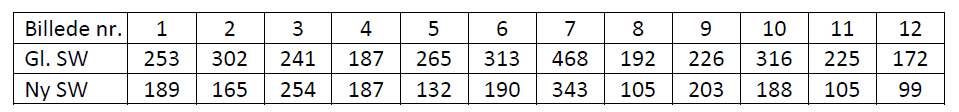

### **ESTIMERET FORBEDRING**

For at finde den estimeret forbedring tages differencen mellem gammel og ny værdi og gennemsnittet af dette. Det gøres ved, at anvende følgende udtryk.


$$\delta^ˆ =\overline{d} =\frac{1}{n}\sum_{i=1}^n \left(X_{1i} -X_2 \right)$$


measurements = 12;
OldData = [253, 302, 241, 187, 265, 313, 468, 192, 226, 316, 225, 172];
NewData = [189, 165, 254, 187, 132, 190, 343, 105, 203, 188, 105, 99];

Delta = 1 / measurements * sum(OldData - NewData)

Delta = 83.3333

Den estimeret forbedring er bestemt til at være 83.3333 sekunder.

### STATISTIK TEST

Der bør anvendes en parret t-test som oftest anvendes til at teste på data fra før og efter målinger.

### HYPOTESER

Der opstilles en null hypotese hvor den forventede tidsændring er lig med 2 minutter, altså 120 sekunder. Alternativ er den forskellig fra de 120 sekunder.

$H_0 :$ forventet tidsændring $\left(\delta \right)=120$

$H_1 :$ forventet tidsændring $\left(\delta \right)\not= 120$

### SAMPLE VARIANS

For at bestemme sample variansen anvendes, at


$$s_d^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(d_i -\bar{d} \right)}^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(X_{1i} -X_{2i} -\bar{d} \right)}^2$$


SampleVariance = (1 / (measurements - 1)) * ...
    sum(((OldData - NewData) - Delta).^2)

SampleVariance = 2.9413e+03

Sample variansen er dermed bestemt til at være 2941.3.

### P-VÆRDIEN

For at bestemme p værdien anvendes, at


$$p=2\cdot \left(1-t_{\mathrm{cdf}} \left(|t|,n-1\right)\right)$$


hvor 


$$t=\frac{\overline{d} -\delta }{\frac{s_d }{\sqrt{n}}}$$


t = (Delta - 120) / (sqrt(SampleVariance) / sqrt(measurements));

PValue = 2 * (1 - tcdf(abs(t), measurements -1))

PValue = 0.0390

P værdien er dermed bestemt til at være 0.039. 

### KONFIDENSINTERVALLET

For at bestemme konfidensintervallet anvendes, at


$$\delta_{\pm } =\bar{d} \pm t_0 \cdot \frac{s_d }{\sqrt{n}}$$


TZero = tinv(0.975, measurements - 1);

Confidens.Min = Delta - TZero * (sqrt(SampleVariance) / sqrt(measurements));
Confidens.Max = Delta + TZero * (sqrt(SampleVariance) / sqrt(measurements));

Confidens

Confidens = struct with fields:
    Min: 48.8747
    Max: 117.7920


Dermed er konfidensintervallet bestemt til at være [48.8747; 117.7920].

### SIGNIFIKANSNIVEAU

Da p værdien er under et 5% signifikansniveau vist som følgende


$$p<0\ldotp 05$$


må antagelsen om en forbedring på 2 minutter forkastes.

## **FORÅR 2016**

Der måles højden på studerende i en klasse, der består af 19 kvinder og 35 mænd. Højderne antages at være normalfordelt. Middelværdien for kvinder i klassen er $\hat{\mu_1 } =1\ldotp 68m$, med en estimeret varians på $\sigma_1^2 =0\ldotp 10$. Middelværdien for mænd i klassen er $\hat{\mu_1 } =1\ldotp 78m$, med en estimeret varians på $\sigma_1^2 =0\ldotp 20$.

Women.Sigma = 0.1;
Women.Mu = 1.68;
Women.Amount = 19;

Men.Sigma = 0.20;
Men.Mu = 1.78;
Men.Amount = 35;

### **HYPOTESE**

Der opstilles en hypotese test for at bestemme om middelværdien af mænd og kvinder i klassen er den samme.


$$H_0 :$$
  
$$\mu_1 =\mu_2$$



$$H_1 :$$
  
$$\mu_1 \not= \mu_2$$


### **STATISTIK TEST**

Da varianserne er ukendte og data er normal-fordelt anvendes en t-test på forskellen af middelværdiernerne.

### **ESTIMERING AF VÆRDIER**

Estimeringen af forskellen i middelværdierne kan bestemmes som følgende.


$$\delta^ˆ =|\overline{x_1 } -\overline{x_2 } |$$


Delta = abs(Women.Mu - Men.Mu)

Delta = 0.1000

Forskellen i middelværdierne er bestemt til at være 0.1. Dernæst til at bestemme forskellen i standard afvigelsen og dertil  anvendes, at


$$s^2 =\frac{1}{n_1 +n_2 -2}\left\lbrack \left(n_1 -1\right)\cdot s_1^2 +\left(n_2 -1\right)\cdot s_2^2 \right\rbrack$$


PooledVariance = sqrt((1 / (Women.Amount + Men.Amount - 2)) ...
    * ((Women.Amount - 1)*Women.Sigma + (Men.Amount - 1)*Men.Sigma))

PooledVariance = 0.4067

Forskellen i standard afvigelsen er dermed bestemt til at være 0.4067.

### **T-TEST**

Der anvendes nu en t-test til test af hypotesen. For at undersøge om NULL hypotesen kan afvises med et signifikansniveau på 0.05 anvendes, at


$$t=\frac{\left(\overline{x_1 } -\overline{x_2 } \right)-\delta }{s\cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}},\;\;p=2\cdot \left(1-t_{\mathrm{cdf}} \left(|t|,n_1 +n_2 -2\right)\right)$$


t = (Delta - 0) / (PooledVariance * sqrt(1/Women.Amount + 1/Men.Amount));

p = 2 * (1 - tcdf(abs(t), Women.Amount + Men.Amount -2))

p = 0.3921

NULL hypotesen kan ikke afvises da $p>0\ldotp 05$. 

### **KONFIDENSINTERVAL**

For at finde 95% konfidens intervallet for $\delta$ anvendes, at 


$$\delta_{\pm } =\left(\overline{x_1 } -\overline{x_2 } \right)\pm t_0 \cdot s\cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}$$


TZero = tinv(0.975, Women.Amount + Men.Amount - 2)

TZero = 2.0066


Step = TZero * PooledVariance * sqrt(1/Women.Amount + 1/Men.Amount);

Interval.Min = Delta - Step;
Interval.Max = Delta + Step;

Interval

Interval = struct with fields:
    Min: -0.1325
    Max: 0.3325


Konfidensintervallet for $\delta$ er dermed bestemt til at være [-0.1325; 0.3325].

## **FORÅR 2016 REEKSAMEN**

I et studie af tandhvalers forventede levetid, registrerede man dødsalderen på individuelle tandhvaler. Der blev i studiet registreret 10 hvaler, der var døde i fangenskab, og 10 hvaler, der var døde i det fri.

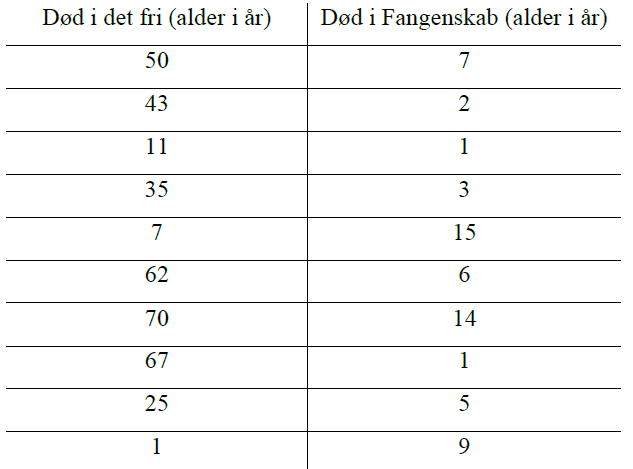

### HYPOTESER

Der opstilles en hypotese test for at bestemme om middelværdien af de to grupper er den samme.


$$H_0 :$$
  
$$\mu_1 =\mu_2$$



$$H_1 :$$
  
$$\mu_1 \not= \mu_2$$


### PARRET VS. UPARRET

Da data ikke opfylder samme betingelser, altså eventuele forhold vil det være optimalt at anvende en uparret test. Dette er vurderet på baggrund af dyr i det fri og i fangenskab som ikke har samme vilkår.

### ESTIMERING AF MIDDELVÆRDI

Den estimerede middelværdi for de to sample set kan bestemmes som følgende.


$$\mu^ˆ =\frac{1}{n}\sum_{i=1}^n x_i$$


Free.Data = [50, 43, 11, 35, 7, 62, 70, 67, 25, 1];
Captivity.Data = [7, 2, 1, 3, 15, 6, 14, 1, 5, 9];

Free.EstimatedMean = mean(Free.Data)

Free = struct with fields:
             Data: [50 43 11 35 7 62 70 67 25 1]
    EstimatedMean: 37.1000


Captivity.EstimatedMean = mean(Captivity.Data) 

Captivity = struct with fields:
             Data: [7 2 1 3 15 6 14 1 5 9]
    EstimatedMean: 6.3000


De to estimerede middelværdier er dermed bestemt til at være 37.1 samt 6.3.

### ESTIMERING AF VARIANS

Den estimerede varians kan bestemmes ud fra de to varianse fra de to sample set givet ved


$$s^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(x_i -\mu^ˆ \right)}^2$$


Free.Variance = (1/(length(Free.Data) - 1)) * ...
    sum((Free.Data - Free.EstimatedMean).^2);

Captivity.Variance = (1/(length(Captivity.Data) - 1)) * ...
    sum((Captivity.Data - Captivity.EstimatedMean).^2);

Den estimerede varians bestemmes nu som følgende.


$$s^2 =\frac{1}{n_1 +n_2 -2}\left\lbrack \left(n_1 -1\right)\cdot s_1^2 +\left(n_2 -1\right)\cdot s_2^2 \right\rbrack$$


Lead = (1 / (length(Free.Data) + length(Captivity.Data) -2));

Back = (length(Free.Data) - 1) * Free.Variance + ... 
    (length(Captivity.Data) - 1) * Captivity.Variance;

PooledVariance = Lead * Back

PooledVariance = 337.1667

Dermed er den estimerede varians bestemt til at være 337.1667.

### UPARRET T-TEST

Der anvendes nu en t-test til test af hypotesen. For at undersøge om NULL hypotesen kan afvises med et signifikansniveau på 0.05 anvendes, at


$$t=\frac{\left(\bar{x_1 } -\bar{x_2 } \right)-\delta }{s\cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}},\;\;p=2\cdot \left(1-t_{\mathrm{cdf}} \left(\left|t\right|,n_1 +n_2 -2\right)\right)$$


t = (Free.EstimatedMean - Captivity.EstimatedMean) / (sqrt(PooledVariance) * ...
    sqrt(1/length(Free.Data) + 1/length(Captivity.Data)));

p = 2 * (1 - tcdf(abs(t), length(Free.Data) + length(Captivity.Data) - 2))

p = 0.0015

NULL hypotesen kan afvises da $p<0\ldotp 05$. 

### KONFIDENSINTERVAL

For at finde 95% konfidens intervallet for $\delta$ anvendes, at 


$$\delta_{\pm } =\left(\overline{x_1 } -\overline{x_2 } \right)\pm t_0 \cdot s\cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}$$


TZero = tinv(0.975, length(Free.Data) + length(Captivity.Data) - 2);

Step = TZero * sqrt(PooledVariance) * sqrt(1/length(Free.Data) + 1/length(Captivity.Data));

Interval.Min = (Free.EstimatedMean - Captivity.EstimatedMean) - Step;
Interval.Max = (Free.EstimatedMean - Captivity.EstimatedMean) + Step;

Interval

Interval = struct with fields:
    Min: 13.5477
    Max: 48.0523


Konfidensintervallet for $\delta$ er dermed bestemt til at være [13.5477; 48.0523].

## **FORÅR 2017**

En kvalitetskontrol måler præcisionen af to forskellige typer gps’er. For begge typer blev målt afvigelsen mellem deres faktiske position $d_{\mathrm{faktisk}}$og gps’ens angivelse $d_{\mathrm{gps}}$.


$$d_i =|d_{i,\mathrm{gps}} -d_{i,\mathrm{faktisk}} |$$


Det kan antages at afvigelserne er normalfordelte. Der er testet 10 gps enheder af type 1 og 12 gps enheder af type 2. For type 1 var middelafvigelsen $\hat{\mu_1 } =5\ldotp 21m$ med en estimeret varians $s_1^2 =1\ldotp 33m^2$. For type 2 var middelafvigelsen $\hat{\mu_2 } =4\ldotp 18m$ med en estimeret varians $s_2^2 =0\ldotp 89m^2$.

TypeOne = struct('Mean', 5.21, 'Variance', 1.33, 'Amount', 10);
TypeTwo = struct('Mean', 4.18, 'Variance', 0.89, 'Amount', 12);

### HYPOTESER

Der opstilles en hypotese test for at bestemme om middelværdien af de to grupper er den samme.


$$H_0 :$$
  
$$\mu_1 =\mu_2$$



$$H_1 :$$
  
$$\mu_1 \not= \mu_2$$


### ESTIMERING AF FORSKEL I MIDDELVÆRDI

Estimeringen af forskellen i middelværdierne kan bestemmes som følgende.


$$\delta^ˆ =|\overline{x_1 } -\overline{x_2 } |$$


Delta = abs(TypeOne.Mean - TypeTwo.Mean)

Delta = 1.0300

Forskellen i middelværdierne er bestemt til at være 1.03.

### ESTIMERING AF VARIANSEN FOR FORSKELLEN

For at bestemme forskellen i variansen anvendes, at


$$s^2 =\frac{1}{n_1 +n_2 -2}\left\lbrack \left(n_1 -1\right)\cdot s_1^2 +\left(n_2 -1\right)\cdot s_2^2 \right\rbrack$$


PooledVariance = (1 / (TypeOne.Amount + TypeTwo.Amount -2)) ...
    * ((TypeOne.Amount - 1)*TypeOne.Variance + (TypeTwo.Amount -1)*TypeTwo.Variance)

PooledVariance = 1.0880

Forskellen i variansen er dermed bestemt til at være 1.088.

### **T-TEST**

Der anvendes nu en t-test til test af hypotesen. For at undersøge om NULL hypotesen kan afvises med et signifikansniveau på 0.05 anvendes, at


$$t=\frac{\left(\overline{x_1 } -\overline{x_2 } \right)-\delta }{s\cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}},\;\;p=2\cdot \left(1-t_{\mathrm{cdf}} \left(|t|,n_1 +n_2 -2\right)\right)$$


t = (Delta - 0) / (sqrt(PooledVariance) * sqrt(1/TypeOne.Amount + 1/TypeTwo.Amount));

p = 2 * (1 - tcdf(abs(t), TypeOne.Amount + TypeTwo.Amount -2))

p = 0.0319

NULL hypotesen kan afvises da $p<0\ldotp 05$. 

### **KONFIDENSINTERVAL**

For at finde 95% konfidens intervallet for $\delta$ anvendes, at 


$$\delta_{\pm } =\left(\overline{x_1 } -\overline{x_2 } \right)\pm t_0 \cdot s\cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}$$


TZero = tinv(0.975, TypeOne.Amount + TypeTwo.Amount - 2);

Step = TZero * sqrt(PooledVariance) * sqrt(1/TypeOne.Amount + 1/TypeTwo.Amount);

Interval.Min = Delta - Step;
Interval.Max = Delta + Step;

Interval

Interval = struct with fields:
    Min: 0.0984
    Max: 1.9616


Konfidensintervallet for $\delta$ er dermed bestemt til at være [0.0984; 1.9616].

## **FORÅR 2017 REEKSAMEN**

For en bestemt type batterier angives i specifikationen fra leverandøren, at levetiden T for batterierne er normalfordelt med en middellevetid på 3000 timer med en standard afvigelse på 100 timer: $T\sim N\left(3000,{100}^2 \right)$. Der udtages tilfældigt 12 batterier af pågældende type. Ved en test måles levetiden af disse til:

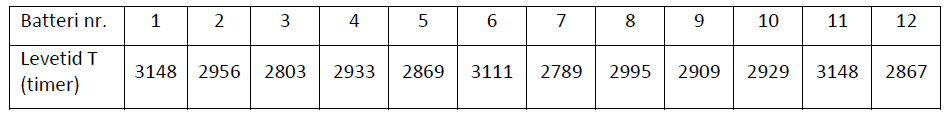

### HYPOTESE

Der opstilles en hypotese test for at bestemme om middelværdien af levettiden er lig med middel af de målte levetid.


$$H_0 :$$
  
$$\mu_T =T=3000$$



$$H_1 :$$
  
$$\mu_t \not= T=3000$$


### MIDDELVÆRDI

For at bestemme den estimerede middelværid af batteri levetiden anvendes, at 


$$\overline{x} =\mu^ˆ =\frac{1}{n}\sum_{i=1}^n x_i$$


Battery = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12];
Lifetime = [3148, 2956, 2803, 2933, 2869, 3111, 2789, 2995, 2909, 2929, 3148, 2867];

MeanLifeTime = (1 / length(Battery)) * sum(Lifetime) 

MeanLifeTime = 2.9548e+03

Den estimerede middellevetid for et batteri er bestemt til at være 2453.5.

### Z-TEST

Der laves en z-test hvor der gælder, at


$$Z=\frac{\overline{x} -\mu }{\frac{\sigma }{\sqrt{n}}}$$


sigma = 100;

Z = (MeanLifeTime - 3000) / (sigma / sqrt(length(Battery)))

Z = -1.5675

Z er dermed bestemt til at være -1.5675. For at bestemme om NULL hypotesen kan afvises findes p-værdien.

p = 2 * abs(1 - normcdf(abs(Z), 0, 1))

p = 0.1170

Da p værdien er større end 0.05 kan null hypotesen ikke afvises.

### KONFIDENSINTERVAL

For at bestemme 95% konfidensintervallet anvendes, at 


$$\mu_{\pm } =\overline{x} \pm 1\ldotp 96\cdot \frac{\sigma }{\sqrt{n}}$$


clear mu
delta = 1.96 * (sigma / sqrt(length(Battery)));

mu.min = MeanLifeTime - delta;
mu.max = MeanLifeTime + delta;

mu

mu = struct with fields:
    min: 2.8982e+03
    max: 3.0113e+03


Konfidensintervallet for $\mu$ er dermed bestemt til at være [2898.2; 3011.3].

## **FORÅR 2018**

Til kvalitetssikring af en produktion er udviklet et automatisk overvågningssystem, der skal registrere om en komponent er monteret korrekt. Overvågningssystemet skal i 95% af tilfældene registrere komponenterne korrekt, dvs. fejl-monterede komponenter registreres som fejl og korrekt-monterede komponenter registreres som korrekte.

For at undersøge om systemet overholder dette krav laves en række måleserier på et produkt A, hvor der testes om overvågningssystemets succesrate er præcis 95%. Testen består af i alt 15 måleserier. Hver serie består af 100 enheder, hvor antallet af korrekte registreringer (successer) noteres.

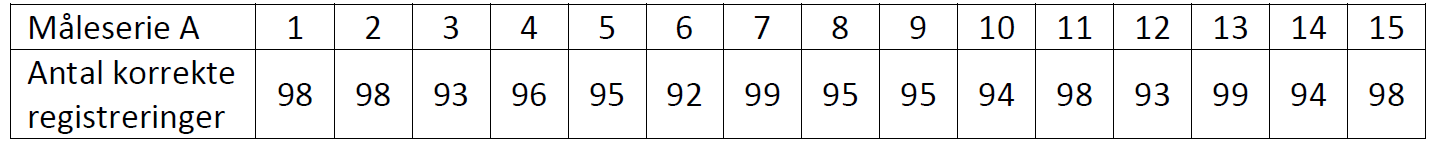

### ESTIMERET SUCCESRATE - SANDSYNLIGHED

ProductA = [98, 98, 93, 96, 95, 92, 99, 95, 95, 94, 98, 93, 99, 94, 98];
Length = length(ProductA);

ProductsInSeries = 100;
Measurements = Length * ProductsInSeries;

SuccesRate = sum(ProductA) / Measurements;

Den estimerede succesrate er bestemt til at være 0.9580.

### TEST STATISTIK

Da testen er baseret på succes eller fiasko anvendes en binomialfordeling hvor følgende betingelser skal være opfyldt.


$$\mathrm{np}>5\;\mathrm{og}\;n\left(1-p\right)>5$$


hvor 

N = Measurements; P = SuccesRate;

N * P 

ans = 1437

N*(1-P)

ans = 63.0000

Der opstilles en null hypoteser samt en alternativ hypotese som følgende.


$$H_0 :$$
  
$$p=0\ldotp 95$$



$$H_1 :$$
  
$$p\not= 0\ldotp 95$$


### P-VÆRDI

For at bestemme p værdien anvendes først, at


$$Z=\frac{X-E\left\lbrack X\right\rbrack }{\sqrt{\mathrm{Var}\left(X\right)}}=\frac{X-\mathrm{np}}{\sqrt{\mathrm{np}\left(1-p\right)}}$$


Z = (sum(ProductA) - Measurements * 0.95) / sqrt(Measurements * 0.95*(1-0.95))

Z = 1.4216

Z er dermed bestemt til at være 1.4216. For at bestemme om NULL hypotesen kan afvises findes p-værdien.

p = 2 * abs(1 - normcdf(abs(Z), 0, 1))

p = 0.1551

Null hypotesen kan altså ikke afvises da p værdien er større end 0.05.

### KONFIDENSINTERVAL

For at bestemme konfidensintervallet anvendes, at


$$p_{\pm } =\frac{1}{n+1\ldotp {96}^2 }\left\lbrack x+\frac{1\ldotp {96}^2 }{2}\pm 1\ldotp 96\cdot \sqrt{\frac{x\left(n-x\right)}{n}+\frac{1\ldotp {96}^2 }{4}}\right\rbrack$$


x = sum(ProductA);
n = Measurements;

step = (1/(n+1.96^2));

clear delta Interval
delta.one = x + (1.96^2 / 2);
delta.two = 1.96 * sqrt( ((x*(n-x))/n) + ((1.96^2)/4));

Interval.min = step * (delta.one - delta.two);
Interval.max = step * (delta.one + delta.two);

Interval

Interval = struct with fields:
    min: 0.9466
    max: 0.9670


### TEST AF DATASÆT

For at undersøge om de to datasæt er forskellige anvendes en uparret samneligningstest af to populationer med ukendt varians også bekendt som uparret t-test. Testen skal være uparret der der ikke er en relation mellem en enhed fra det ene produkt til en enhed fra det andet produkt. Desuden er det et antal forskellige målinger. De to populationer antages at have ens men ukendt varians.

### NULL HYPOTESE - TEST MV.

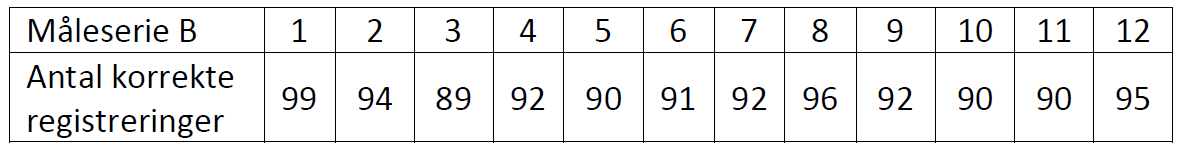

Der opstilles en hypotese test for at bestemme om middelværdien af de to grupper er den samme. Altså om det gennemsnitslige antal korrekt monitorerede enheder pr. måling er ens for de to produkter.


$$H_0 :$$
  
$$\mu_1 =\mu_2$$



$$H_1 :$$
  
$$\mu_1 \not= \mu_2$$


Det gennemsnitslige antal korrekte enheder pr. måling estimeres som følgendes.


$$n_A =\frac{N_{\mathrm{Akorrekte}} }{15}$$



$$n_B =\frac{N_{\mathrm{Bkorrekte}} }{12}$$


ProductB = [99, 94, 89, 92, 90, 91, 92, 96, 92, 90, 90, 95];

Na = sum(ProductA) / 15;
Nb = sum(ProductB) / 12;

Den poolede varians bestemmes ud fra de to sample varianser hvilke beregnes som følgende.


$$s^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(x_i -\mu^ˆ \right)}^2$$



$${s_p }^2 =\frac{1}{n_1 +n_2 -2}\left\lbrack \left(n_1 -1\right)\cdot s_1^2 +\left(n_2 -1\right)\cdot s_2^2 \right\rbrack$$


clear SampleVariance
SampleVariance.A =  (1 / (15 - 1)) * sum((ProductA - Na).^2);
SampleVariance.B = (1 / (12 - 1)) * sum((ProductB - Nb).^2);

PooledVariance = (1 / (15 + 12 - 2)) * (((15-1)*SampleVariance.A) + ((12-1)*SampleVariance.B))

PooledVariance = 7.0160

Dernæst anvendes t-værdi som bestemmes ud fra følgende.


$$t=\frac{\overline{x_1 } -\overline{x_2 } -\delta }{s_p \cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}}$$


t = (Na - Nb) / (sqrt(PooledVariance) * sqrt(1/15 + 1/12));

p = 2 * (1 - tcdf(abs(t), 15 + 12 - 2))

p = 0.0036

Da p værdien er under 0.05 kan null hypotesen afvises og overvågningssystemet virker forskelligt på de to typer produkter.

## **FORÅR 2018 REEKSAMEN**